# Spike Count Analysis - Entropy & Fano Factor

## Create a folder for the processed data that will be compile and analyzed

targetdir = "C:\Users\LPASCU2\OneDrive - Emory University\MATLAB_CODE\ephys-songbird\data\processed\compiled_cases";
figct = 0;

## Compile data that will be analyzed.

### Cases subset: JUVENILE

juv_early = struct();
getTrials = {};
juv_params = {};

#### CHOOSE CASES FOR ANALYSIS 

% Extract spikes starting from t-premotor_win (sec prior to syllable onset)
premotor_win = 0.2; % parameter for making new case file or finding an existing case file 

cd 'J:\MINI DATASET'

%%% Query for BIRD 1 %%%
birdname1 = 'br177yw112';
days1 = [62 661 662 73 86 88];%[62 661 662 68 73 86 88];
syls1 = 'bcdghjkrm';
file_exist = 0; % date file was generated,'YYYY-MM-DD', if making new files

% Extract Data from given bird, neuron/days, syls into a Data Structure
getTrials = get_spikes_acs_data(birdname1,days1,syls1,premotor_win,file_exist);

day = 62

Done. There are 151 clean trials and 0 trials with artifact.
Elapsed time is 3.114136 seconds.
Done. There are 145 clean trials and 0 trials with artifact.
Elapsed time is 0.793915 seconds.
Done. There are 177 clean trials and 0 trials with artifact.
Elapsed time is 0.829249 seconds.
Done. There are 6 clean trials and 0 trials with artifact.
Elapsed time is 0.648233 seconds.
Done. There are 4 clean trials and 0 trials with artifact.
Elapsed time is 0.655150 seconds.


day = 661

Done. There are 75 clean trials and 0 trials with artifact.
Elapsed time is 2.892058 seconds.
Done. There are 71 clean trials and 0 trials with artifact.
Elapsed time is 0.680250 seconds.
Done. There are 79 clean trials and 0 trials with artifact.
Elapsed time is 0.660816 seconds.
Done. There are 2 clean trials and 0 trials with artifact.
Elapsed time is 0.592724 seconds.
Done. There are 21 clean trials and 0 trials with artifact.
Elapsed time is 0.630197 seconds.
Done. There are 18 clean trials and 0 trials with artifact.
Elapsed time is 0.624210 seconds.
Done. There are 12 clean trials and 0 trials with artifact.
Elapsed time is 0.701927 seconds.


day = 662

Done. There are 112 clean trials and 0 trials with artifact.
Elapsed time is 4.433216 seconds.
Done. There are 104 clean trials and 0 trials with artifact.
Elapsed time is 1.187304 seconds.
Done. There are 155 clean trials and 0 trials with artifact.
Elapsed time is 1.250949 seconds.
Done. There are 2 clean trials and 0 trials with artifact.
Elapsed time is 1.098987 seconds.
Done. There are 1 clean trials and 0 trials with artifact.
Elapsed time is 1.072972 seconds.
Done. There are 70 clean trials and 0 trials with artifact.
Elapsed time is 1.156491 seconds.
Done. There are 58 clean trials and 0 trials with artifact.
Elapsed time is 1.231507 seconds.
Done. There are 23 clean trials and 0 trials with artifact.
Elapsed time is 1.164847 seconds.


day = 73

Done. There are 347 clean trials and 0 trials with artifact.
Elapsed time is 11.445663 seconds.
Done. There are 553 clean trials and 0 trials with artifact.
Elapsed time is 4.509967 seconds.
Done. There are 532 clean trials and 0 trials with artifact.
Elapsed time is 4.714540 seconds.
Done. There are 329 clean trials and 0 trials with artifact.
Elapsed time is 4.363091 seconds.
Done. There are 247 clean trials and 0 trials with artifact.
Elapsed time is 4.259122 seconds.
Done. There are 252 clean trials and 0 trials with artifact.
Elapsed time is 4.448233 seconds.
Done. There are 208 clean trials and 0 trials with artifact.
Elapsed time is 4.240720 seconds.
Done. There are 195 clean trials and 0 trials with artifact.
Elapsed time is 4.149362 seconds.
Done. There are 352 clean trials and 0 trials with artifact.
Elapsed time is 4.573170 seconds.


day = 86

Done. There are 497 clean trials and 0 trials with artifact.
Elapsed time is 19.374041 seconds.
Done. There are 689 clean trials and 0 trials with artifact.
Elapsed time is 10.746444 seconds.
Done. There are 729 clean trials and 0 trials with artifact.
Elapsed time is 5.850223 seconds.
Done. There are 605 clean trials and 0 trials with artifact.
Elapsed time is 5.969836 seconds.
Done. There are 262 clean trials and 0 trials with artifact.
Elapsed time is 5.377041 seconds.
Done. There are 262 clean trials and 0 trials with artifact.
Elapsed time is 5.635220 seconds.
Done. There are 292 clean trials and 0 trials with artifact.
Elapsed time is 5.453598 seconds.
Done. There are 259 clean trials and 0 trials with artifact.
Elapsed time is 5.581004 seconds.
Done. There are 301 clean trials and 0 trials with artifact.
Elapsed time is 5.427803 seconds.


day = 88

Done. There are 488 clean trials and 0 trials with artifact.
Elapsed time is 24.976910 seconds.
Done. There are 727 clean trials and 0 trials with artifact.
Elapsed time is 13.097179 seconds.
Done. There are 728 clean trials and 0 trials with artifact.
Elapsed time is 6.599094 seconds.
Done. There are 636 clean trials and 0 trials with artifact.
Elapsed time is 5.597691 seconds.
Done. There are 307 clean trials and 0 trials with artifact.
Elapsed time is 5.236846 seconds.
Done. There are 314 clean trials and 0 trials with artifact.
Elapsed time is 5.206878 seconds.
Done. There are 348 clean trials and 0 trials with artifact.
Elapsed time is 5.109137 seconds.
Done. There are 320 clean trials and 0 trials with artifact.
Elapsed time is 5.142585 seconds.
Done. There are 501 clean trials and 0 trials with artifact.
Elapsed time is 5.382327 seconds.



%%% Query for BIRD 2 %%%
birdname2 = 'br173gr56';
days2 = [78 801 802 803 811 812 153]; %[78 801 802 803 811 812];
syls2 = 'bcfghjkpqrs'; %'bcfghjkpqrs'
file_exist = 0;

getTrials2 = get_spikes_acs_data(birdname2,days2,syls2,premotor_win,file_exist);

day = 78

Done. There are 151 clean trials and 0 trials with artifact.
Elapsed time is 11.055190 seconds.
Done. There are 444 clean trials and 0 trials with artifact.
Elapsed time is 2.644486 seconds.
Done. There are 134 clean trials and 0 trials with artifact.
Elapsed time is 2.382916 seconds.
Done. There are 160 clean trials and 0 trials with artifact.
Elapsed time is 2.414308 seconds.
Done. There are 91 clean trials and 0 trials with artifact.
Elapsed time is 2.329925 seconds.
Done. There are 255 clean trials and 0 trials with artifact.
Elapsed time is 2.470487 seconds.
Done. There are 259 clean trials and 0 trials with artifact.
Elapsed time is 2.469235 seconds.
Done. There are 132 clean trials and 0 trials with artifact.
Elapsed time is 2.403980 seconds.
Done. There are 111 clean trials and 0 trials with artifact.
Elapsed time is 2.369039 seconds.
Done. There are 112 clean trials and 0 trials with artifact.
Elapsed time is 2.360367 seconds.
Done. There are 112 clean trials and 0 trials with

day = 801

Done. There are 41 clean trials and 0 trials with artifact.
Elapsed time is 3.746368 seconds.
Done. There are 125 clean trials and 0 trials with artifact.
Elapsed time is 0.741536 seconds.
Done. There are 40 clean trials and 0 trials with artifact.
Elapsed time is 0.677434 seconds.
Done. There are 34 clean trials and 0 trials with artifact.
Elapsed time is 0.666900 seconds.
Done. There are 31 clean trials and 0 trials with artifact.
Elapsed time is 0.680975 seconds.
Done. There are 78 clean trials and 0 trials with artifact.
Elapsed time is 0.709188 seconds.
Done. There are 77 clean trials and 0 trials with artifact.
Elapsed time is 0.713508 seconds.
Done. There are 41 clean trials and 0 trials with artifact.
Elapsed time is 0.697375 seconds.
Done. There are 38 clean trials and 0 trials with artifact.
Elapsed time is 0.691551 seconds.
Done. There are 21 clean trials and 0 trials with artifact.
Elapsed time is 0.673621 seconds.
Done. There are 38 clean trials and 0 trials with artifact.

day = 802

Done. There are 17 clean trials and 0 trials with artifact.
Elapsed time is 0.967918 seconds.
Done. There are 55 clean trials and 0 trials with artifact.
Elapsed time is 0.272773 seconds.
Done. There are 17 clean trials and 0 trials with artifact.
Elapsed time is 0.244556 seconds.
Done. There are 15 clean trials and 0 trials with artifact.
Elapsed time is 0.235742 seconds.
Done. There are 14 clean trials and 0 trials with artifact.
Elapsed time is 0.246279 seconds.
Done. There are 33 clean trials and 0 trials with artifact.
Elapsed time is 0.264251 seconds.
Done. There are 31 clean trials and 0 trials with artifact.
Elapsed time is 0.260956 seconds.
Done. There are 22 clean trials and 0 trials with artifact.
Elapsed time is 0.247450 seconds.
Done. There are 16 clean trials and 0 trials with artifact.
Elapsed time is 0.244217 seconds.
Done. There are 13 clean trials and 0 trials with artifact.
Elapsed time is 0.260144 seconds.
Done. There are 16 clean trials and 0 trials with artifact.


day = 803

Done. There are 75 clean trials and 0 trials with artifact.
Elapsed time is 3.850763 seconds.
Done. There are 213 clean trials and 0 trials with artifact.
Elapsed time is 1.071643 seconds.
Done. There are 72 clean trials and 0 trials with artifact.
Elapsed time is 0.968850 seconds.
Done. There are 69 clean trials and 0 trials with artifact.
Elapsed time is 0.940169 seconds.
Done. There are 41 clean trials and 0 trials with artifact.
Elapsed time is 0.950465 seconds.
Done. There are 149 clean trials and 0 trials with artifact.
Elapsed time is 1.006181 seconds.
Done. There are 147 clean trials and 0 trials with artifact.
Elapsed time is 0.937369 seconds.
Done. There are 79 clean trials and 0 trials with artifact.
Elapsed time is 0.892048 seconds.
Done. There are 65 clean trials and 0 trials with artifact.
Elapsed time is 0.892186 seconds.
Done. There are 4 clean trials and 0 trials with artifact.
Elapsed time is 0.849898 seconds.
Done. There are 65 clean trials and 0 trials with artifact

day = 811

Done. There are 240 clean trials and 0 trials with artifact.
Elapsed time is 9.419646 seconds.
Done. There are 607 clean trials and 0 trials with artifact.
Elapsed time is 2.853442 seconds.
Done. There are 235 clean trials and 0 trials with artifact.
Elapsed time is 2.554803 seconds.
Done. There are 225 clean trials and 0 trials with artifact.
Elapsed time is 2.564808 seconds.
Done. There are 225 clean trials and 0 trials with artifact.
Elapsed time is 2.583259 seconds.
Done. There are 481 clean trials and 0 trials with artifact.
Elapsed time is 2.800017 seconds.
Done. There are 476 clean trials and 0 trials with artifact.
Elapsed time is 2.820464 seconds.
Done. There are 222 clean trials and 0 trials with artifact.
Elapsed time is 2.574241 seconds.
Done. There are 186 clean trials and 0 trials with artifact.
Elapsed time is 2.527271 seconds.
Done. There are 183 clean trials and 0 trials with artifact.
Elapsed time is 2.479518 seconds.
Done. There are 179 clean trials and 0 trials with

day = 812

Done. There are 136 clean trials and 0 trials with artifact.
Elapsed time is 4.223509 seconds.
Done. There are 348 clean trials and 0 trials with artifact.
Elapsed time is 1.869447 seconds.
Done. There are 132 clean trials and 0 trials with artifact.
Elapsed time is 1.606500 seconds.
Done. There are 126 clean trials and 0 trials with artifact.
Elapsed time is 1.602462 seconds.
Done. There are 127 clean trials and 0 trials with artifact.
Elapsed time is 1.604097 seconds.
Done. There are 278 clean trials and 0 trials with artifact.
Elapsed time is 1.793329 seconds.
Done. There are 274 clean trials and 0 trials with artifact.
Elapsed time is 1.726223 seconds.
Done. There are 130 clean trials and 0 trials with artifact.
Elapsed time is 1.618967 seconds.
Done. There are 110 clean trials and 0 trials with artifact.
Elapsed time is 1.551077 seconds.
Done. There are 109 clean trials and 0 trials with artifact.
Elapsed time is 1.616646 seconds.
Done. There are 105 clean trials and 0 trials with

day = 153

Done. There are 135 clean trials and 0 trials with artifact.
Elapsed time is 4.704388 seconds.
Done. There are 250 clean trials and 0 trials with artifact.
Elapsed time is 1.288823 seconds.
Done. There are 134 clean trials and 0 trials with artifact.
Elapsed time is 1.189438 seconds.
Done. There are 134 clean trials and 0 trials with artifact.
Elapsed time is 1.185413 seconds.
Done. There are 134 clean trials and 0 trials with artifact.
Elapsed time is 1.183235 seconds.
Done. There are 259 clean trials and 0 trials with artifact.
Elapsed time is 1.263731 seconds.
Done. There are 257 clean trials and 0 trials with artifact.
Elapsed time is 1.269259 seconds.
Done. There are 127 clean trials and 0 trials with artifact.
Elapsed time is 1.160349 seconds.
Done. There are 127 clean trials and 0 trials with artifact.
Elapsed time is 1.147927 seconds.



% Combine Cases
struct1 = getTrials; struct2 = getTrials2; 
names = [fieldnames(struct1); fieldnames(struct2)];
struct3 = cell2struct([struct2cell(struct1); struct2cell(struct2)], names, 1);
allCases = struct3;

% Save compiled cases
cd(targetdir)
savefn = 'compiled_cases_2024_02_17.mat';
save(savefn,"allCases","birdname1", "days1", "syls1", "birdname2", "days2", "syls2");

Split br177yw12 syllable 'd' syllables into two clusters for days 73,86,88.

% Array of days you want to loop through
days = [73, 86, 88];

% Loop through each day
for i = 1:length(days)
    day = days(i);
    
    % Construct the variable name for the current day
    neuralcase_varname = sprintf('allCases.br177yw112_d_day%d', day);
    
    % Dynamically access the variable for the current day
    neuralcase = eval(neuralcase_varname);
    
    % Extract data for the current neuralcase
    f1 = neuralcase.weighted_avg_pitch;
    durs = neuralcase.syl_ons_offs(:,2) - neuralcase.syl_ons_offs(:,1);
    recname = neuralcase.recfilename;
    
    % Plotting
    figure; histogram(f1); title(['br177yw112: Day ', num2str(day), ', syllable d']); xlabel('pitch');
    figure; histogram(durs); title(['br177yw112: Day ', num2str(day), ', syllable d']); xlabel('duration (s)');
    
    figure; scatter(durs, f1);
    xlabel('syllable duration (sec)');
    ylabel('fundamental frequency');

    % create matrix of k-means
    acoustics = table(f1, durs);
    X(:,1) = f1; 
    X(:,2) = durs;
    rng('default')


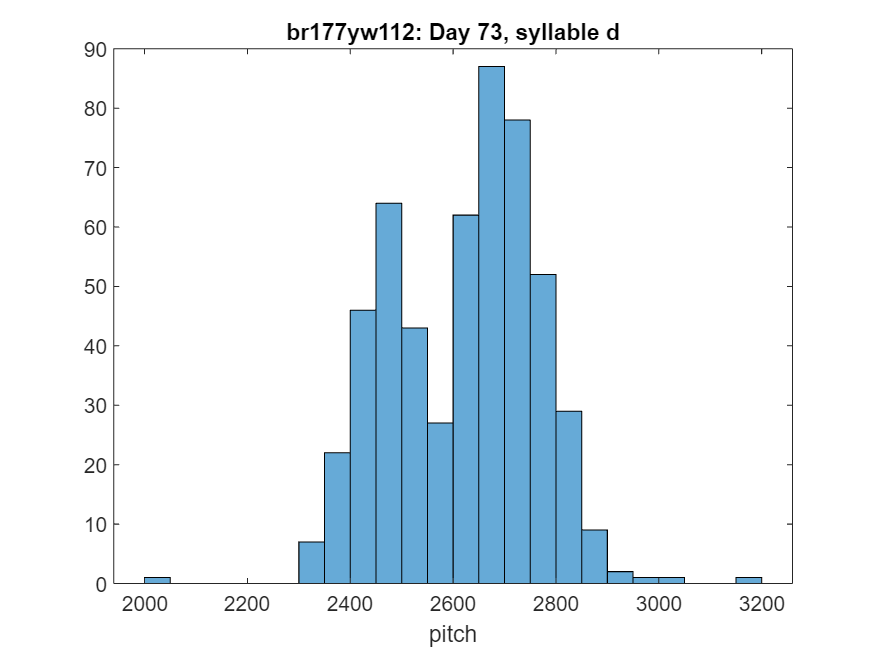

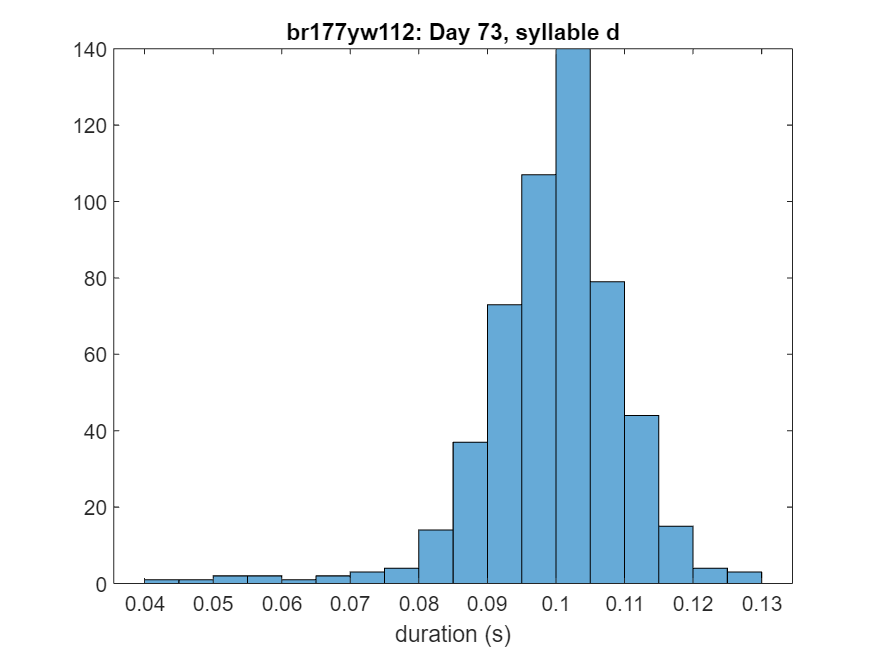

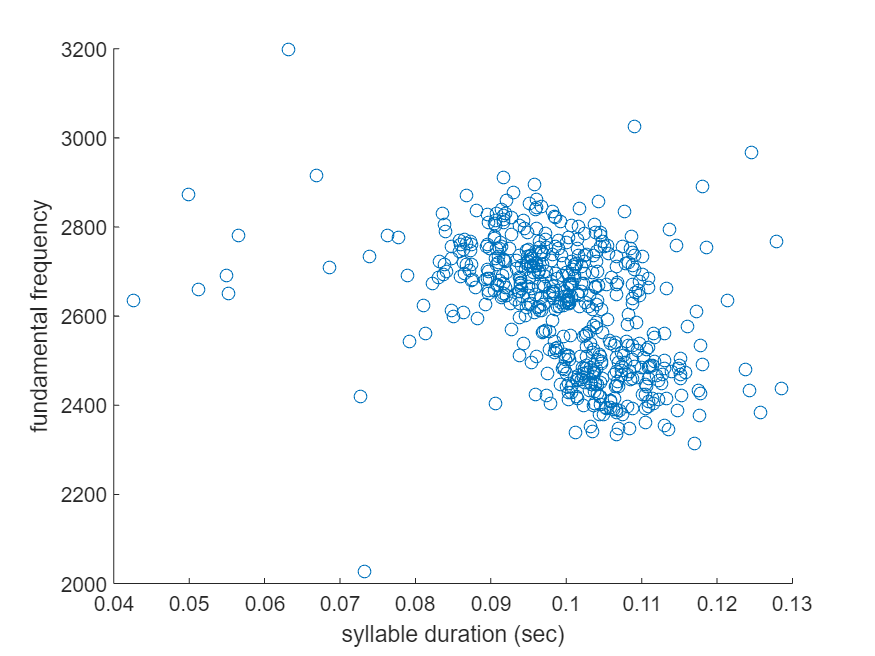

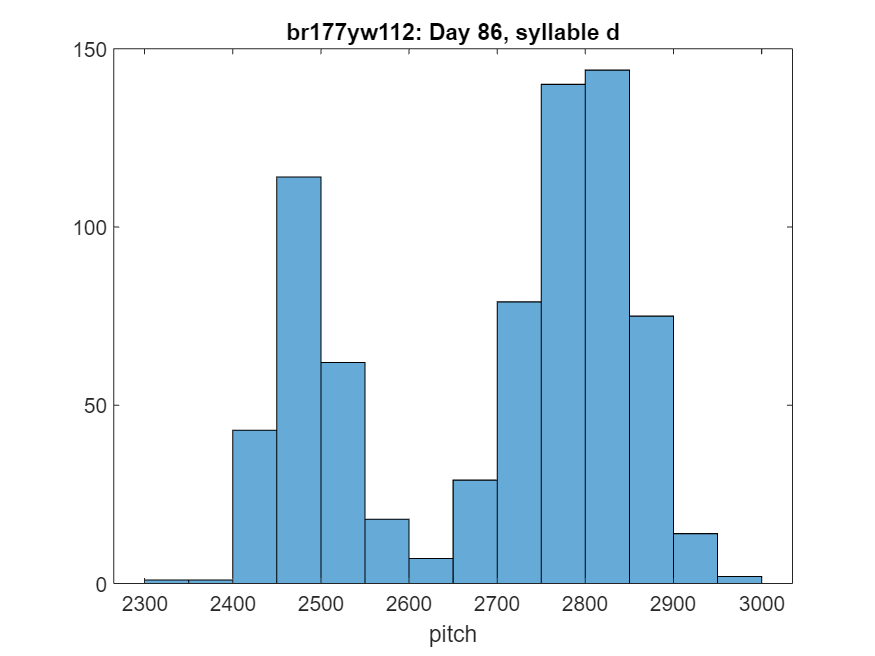

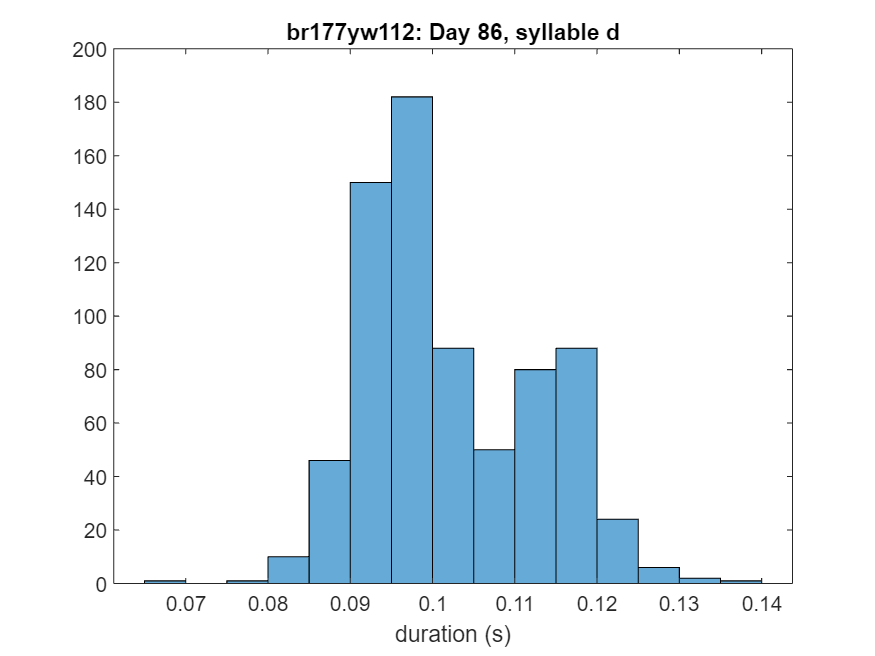

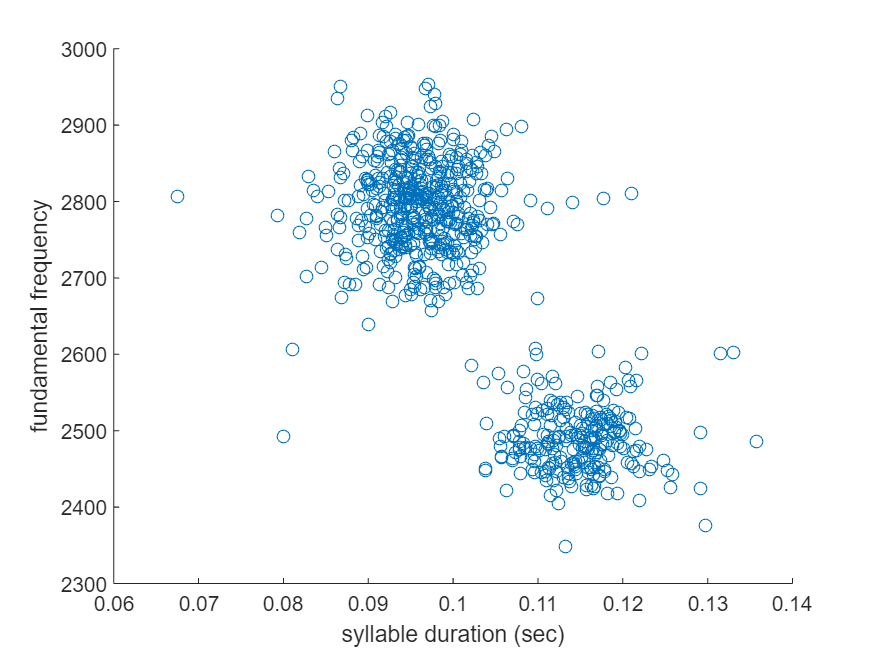

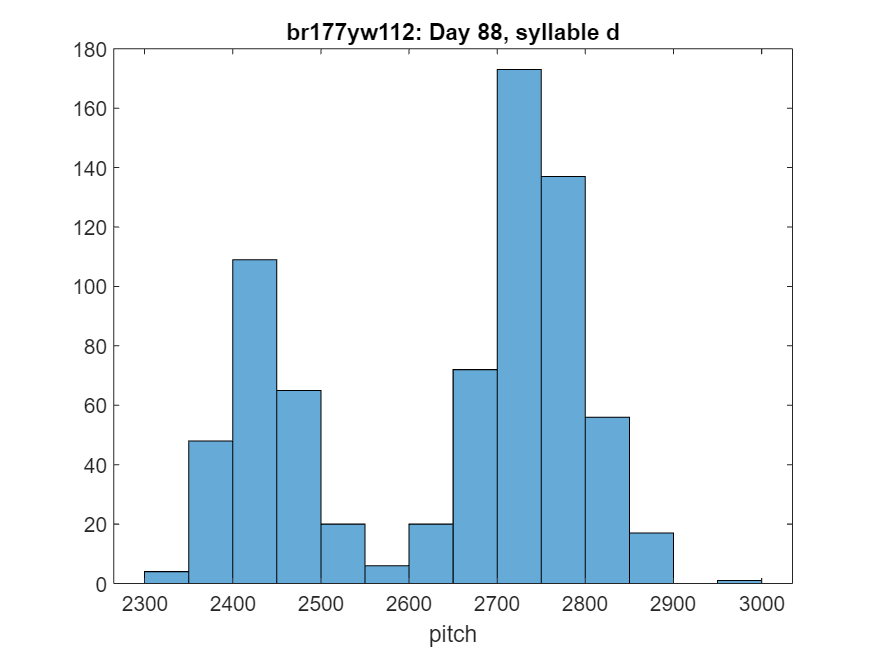

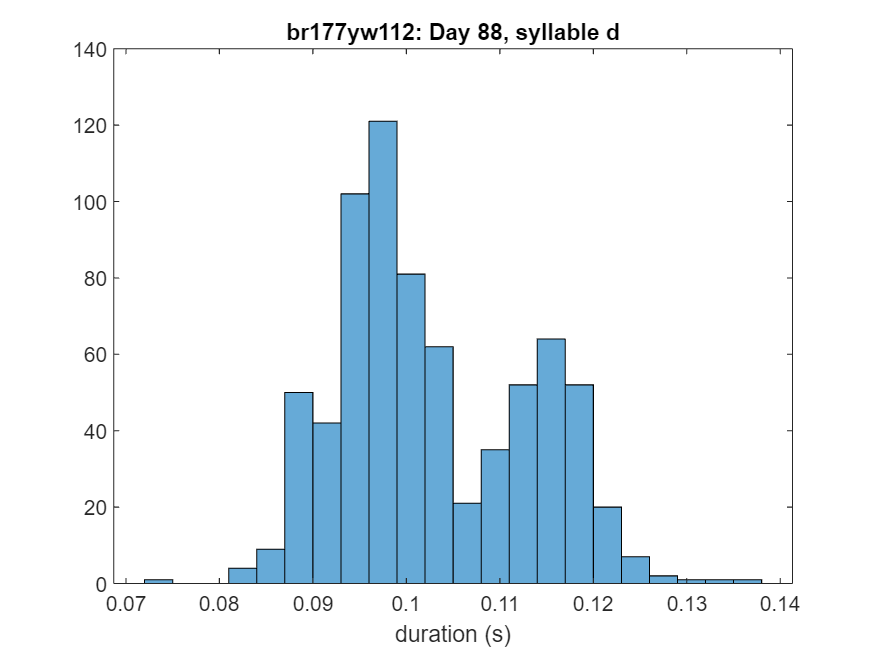

% Perform k-means clustering using specified number of clusters (K value)
K = 2;
[clusterIndices,centroids] = kmeans(X,K);

% Display results

% Display 2D scatter plot (PCA)
figure
[~,score] = pca(X);
clusterMeans = grpstats(score,clusterIndices,"mean");
h2 = gscatter(score(:,1),score(:,2),clusterIndices);
for i = 1:numel(h2)
    h2(i).DisplayName = strcat("Cluster",h2(i).DisplayName);
end
clear h2 i score
hold on
h2 = scatter(clusterMeans(:,1),clusterMeans(:,2),50,"kx","LineWidth",2);
hold off
h2.DisplayName = "ClusterMeans";
clear h2 clusterMeans
legend;
title("First 2 PCA Components of Clustered Data");
xlabel("First principal component");
ylabel("Second principal component");

% Matrix plot
figure
selectedCols = sort([2,1]);
[~,ax] = gplotmatrix(X(:,selectedCols),[],clusterIndices,[],[],[],[],"grpbars");
title("Comparison of Columns in Clustered Data");
clear K
clusterMeans = grpstats(X,clusterIndices,"mean");
hold(ax,"on");
for i = 1 : size(selectedCols,2)
  for j = 1 : size(selectedCols,2)
      if i ~= j  
          scatter(ax(j,i),clusterMeans(:,selectedCols(i)),clusterMeans(:,selectedCols(j)), ...
            50,"kx","LineWidth",1.5,"DisplayName","ClusterMeans");
          xlabel(ax(size(selectedCols,2),i),("Column" + selectedCols(i)));
          ylabel(ax(i,1),("Column" + selectedCols(i)));
      end
   end
end
clear ax clusterMeans i j selectedCols

    % silhouette plot to measure how close each point in one cluster is to points in the neighboring clusters
    [silh3,h] = silhouette(X,clusterIndices,'cityblock');
    xlabel('Silhouette Value')
    ylabel('Cluster')


end

## Run Spike Stats Analysis

    {'br177yw112_b_day62'}



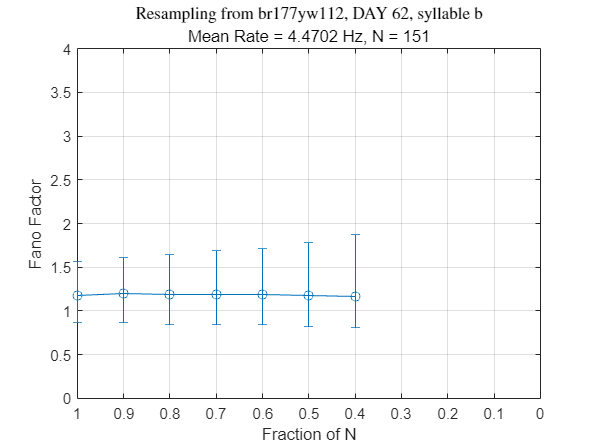

    {'br177yw112_c_day62'}



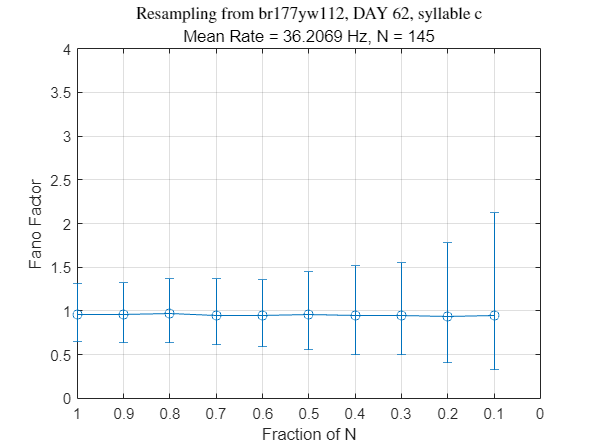

    {'br177yw112_d_day62'}



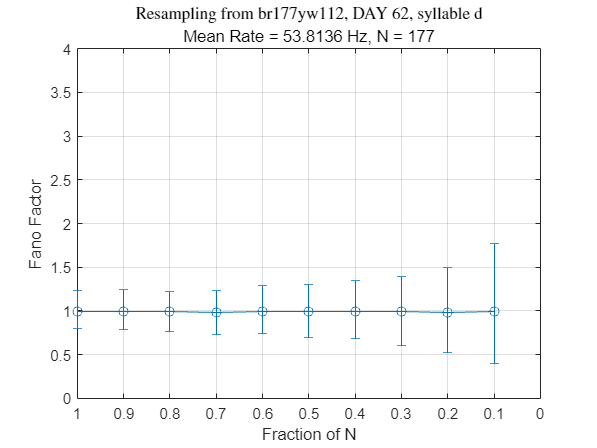

    {'br177yw112_b_day661'}



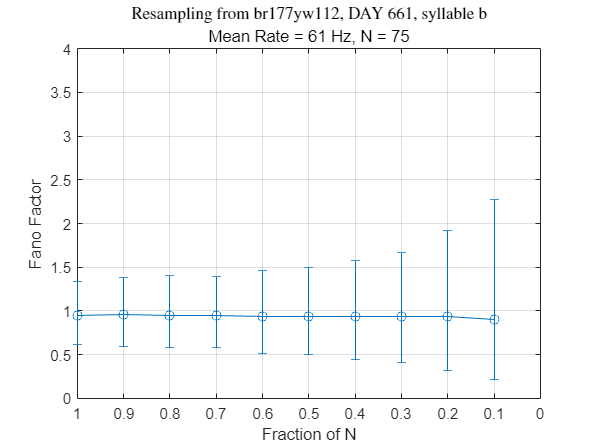

    {'br177yw112_c_day661'}



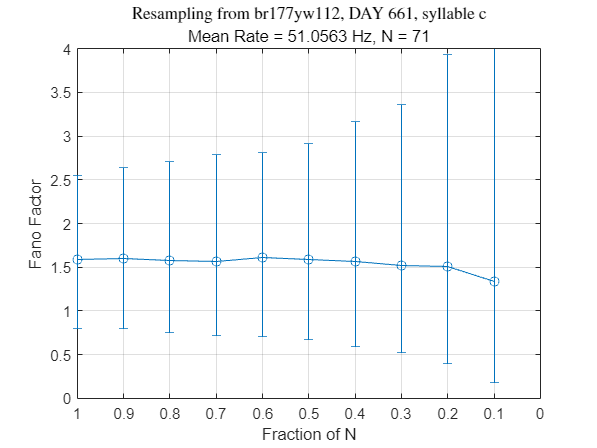

    {'br177yw112_d_day661'}



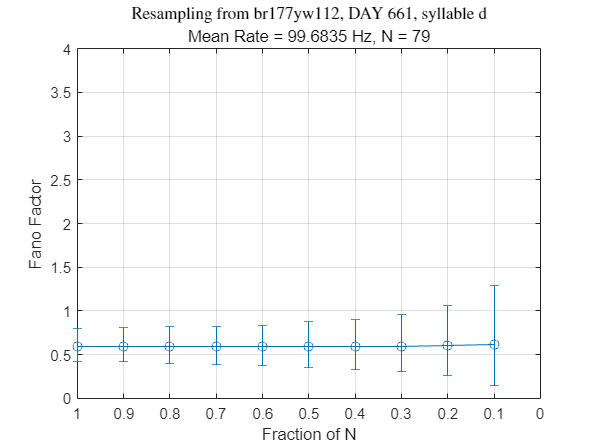

    {'br177yw112_b_day662'}



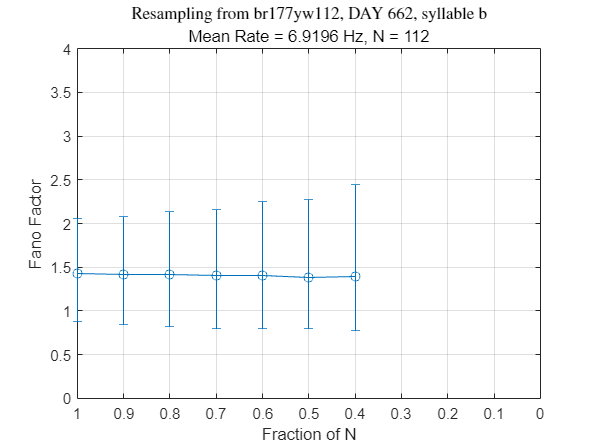

    {'br177yw112_c_day662'}



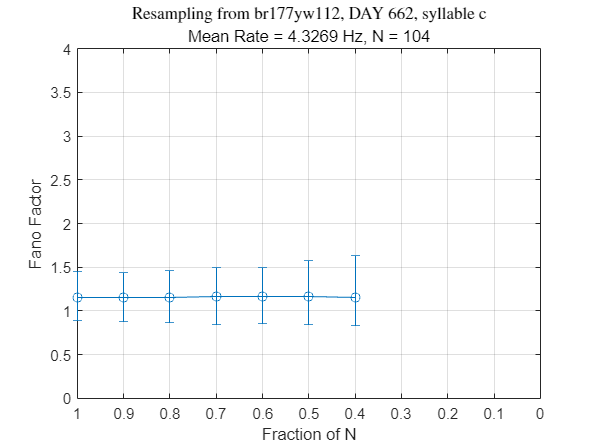

    {'br177yw112_d_day662'}



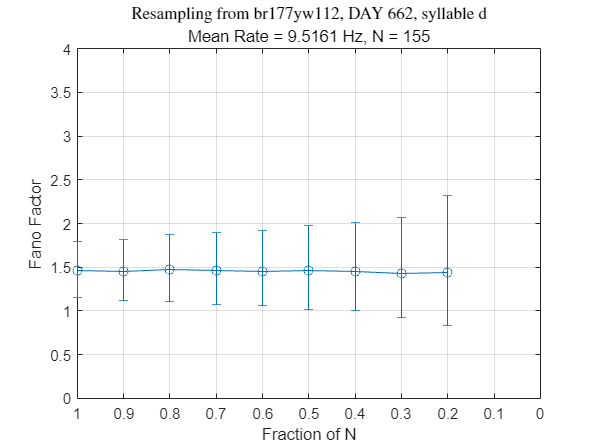

    {'br177yw112_k_day662'}



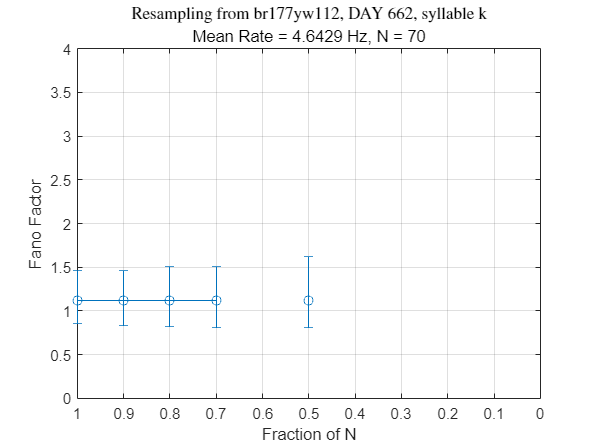

    {'br177yw112_r_day662'}



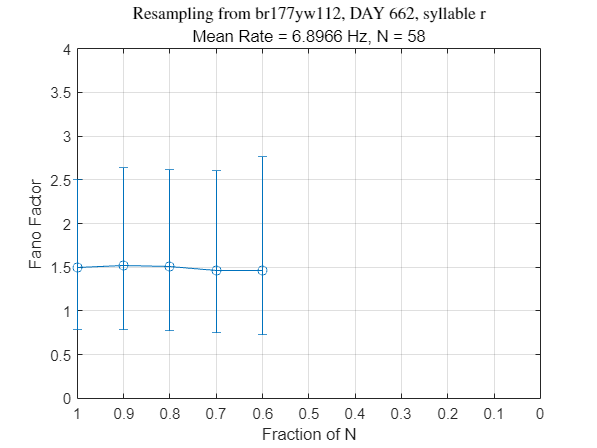

    {'br177yw112_b_day73'}



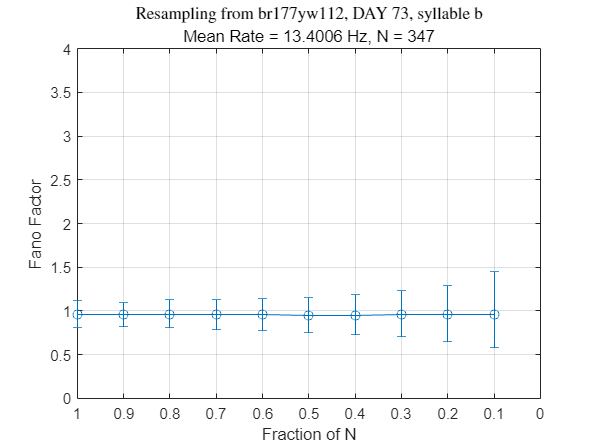

    {'br177yw112_c_day73'}



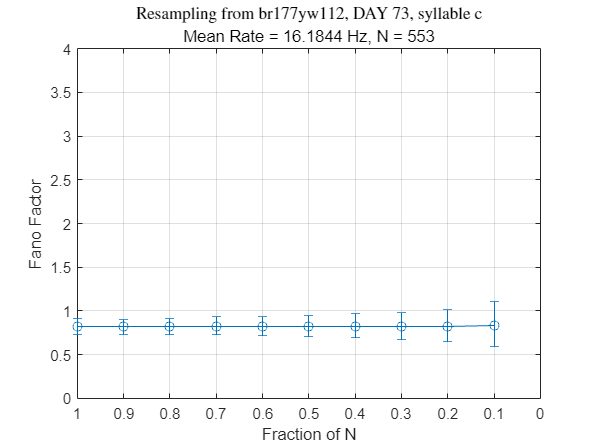

    {'br177yw112_d_day73'}



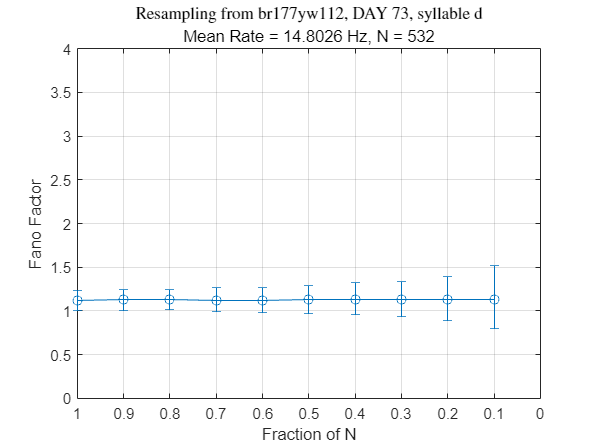

    {'br177yw112_g_day73'}



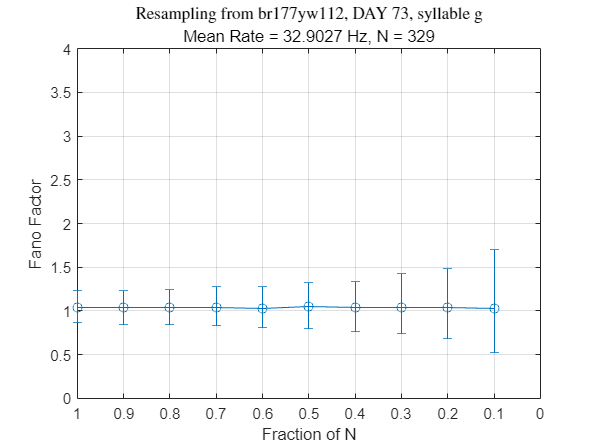

    {'br177yw112_h_day73'}



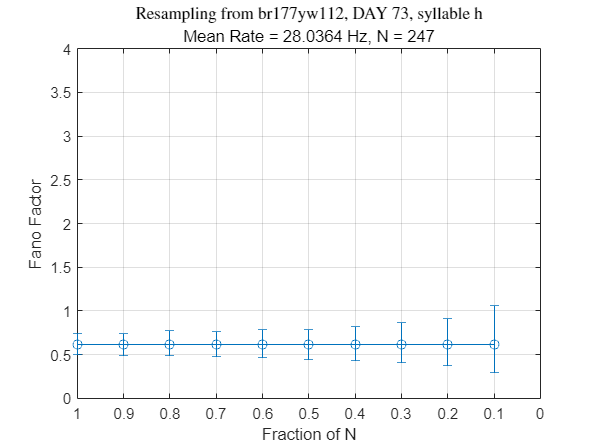

    {'br177yw112_j_day73'}



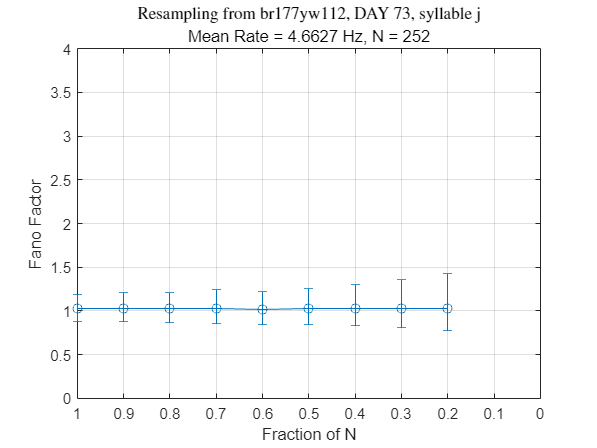

    {'br177yw112_k_day73'}



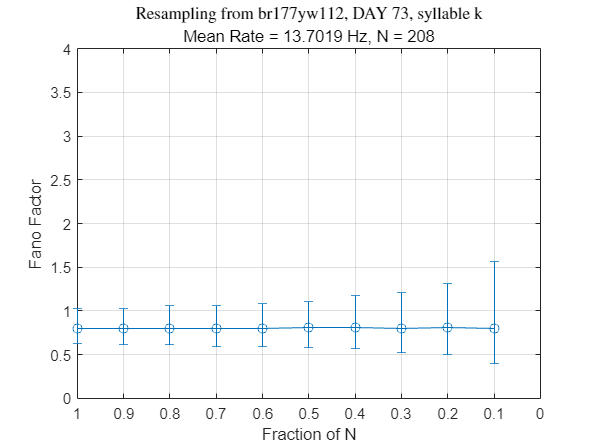

    {'br177yw112_r_day73'}



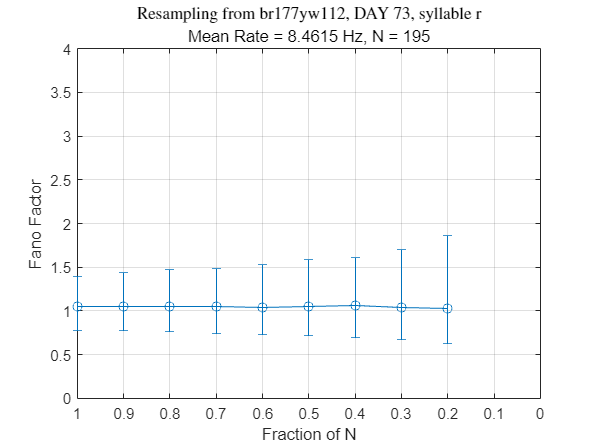

    {'br177yw112_m_day73'}



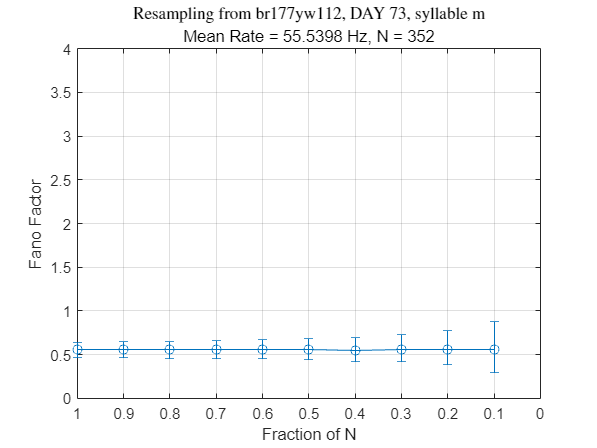

    {'br177yw112_b_day86'}



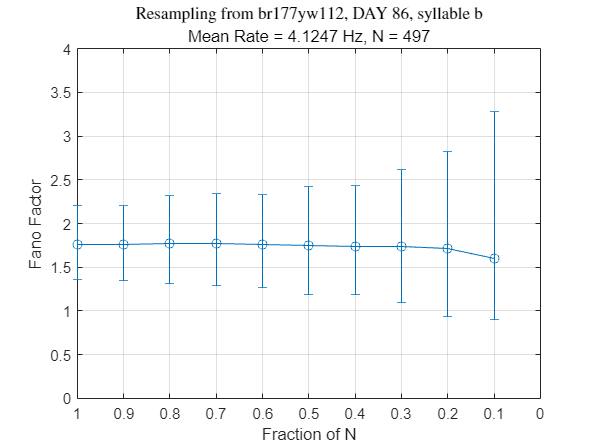

    {'br177yw112_c_day86'}



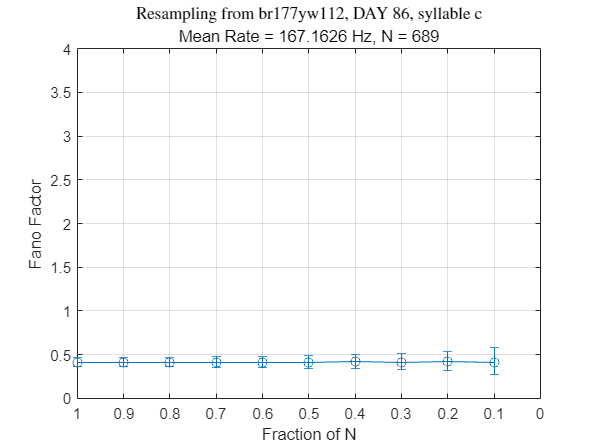

    {'br177yw112_d_day86'}



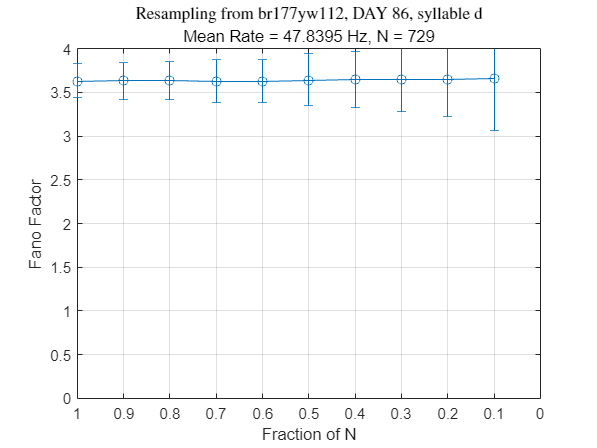

    {'br177yw112_g_day86'}



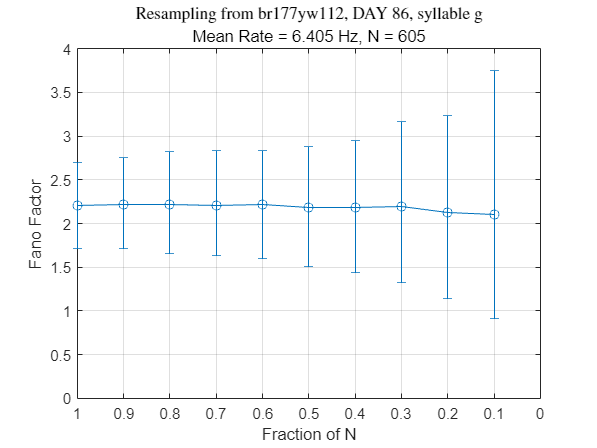

    {'br177yw112_h_day86'}



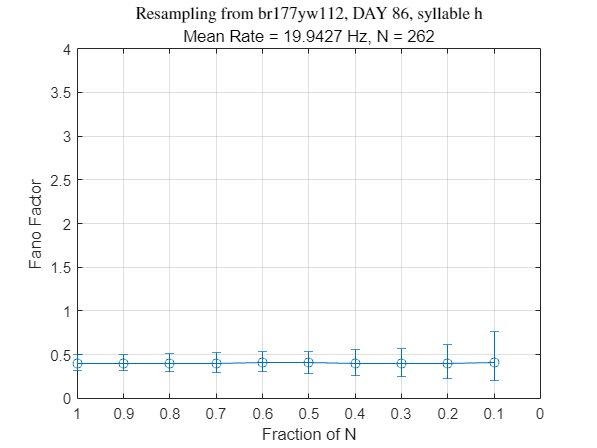

    {'br177yw112_j_day86'}



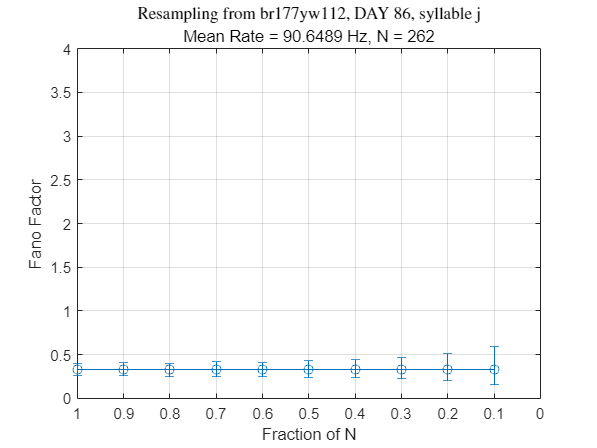

    {'br177yw112_k_day86'}



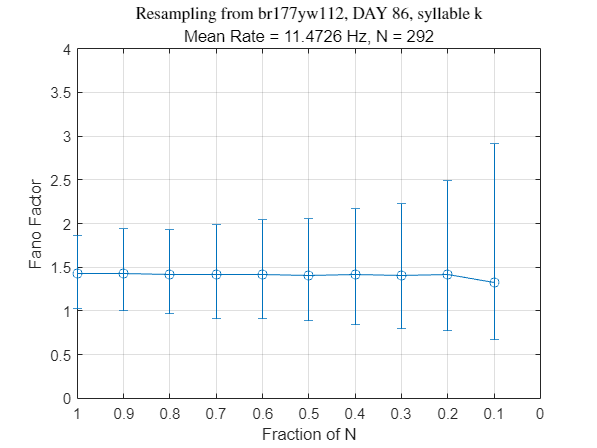

    {'br177yw112_r_day86'}



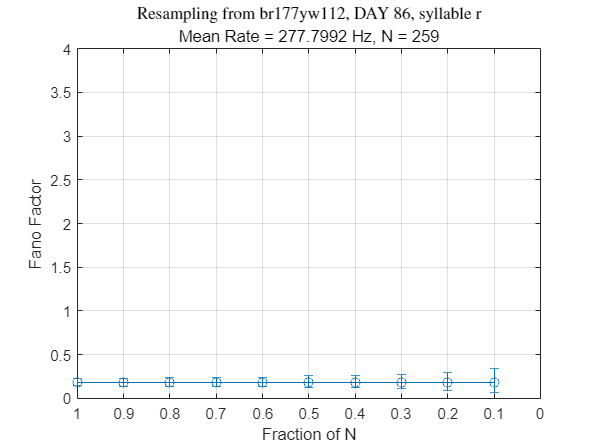

    {'br177yw112_m_day86'}



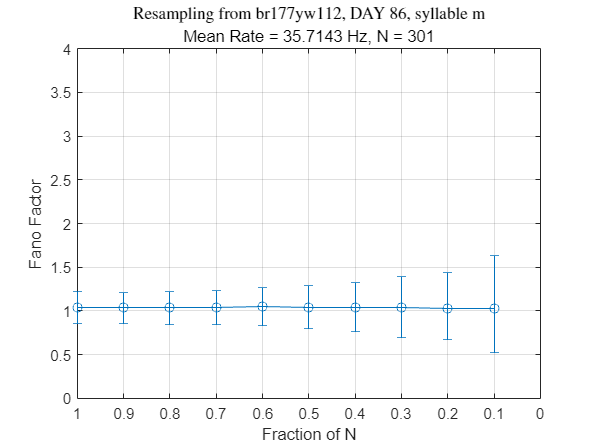

    {'br177yw112_b_day88'}



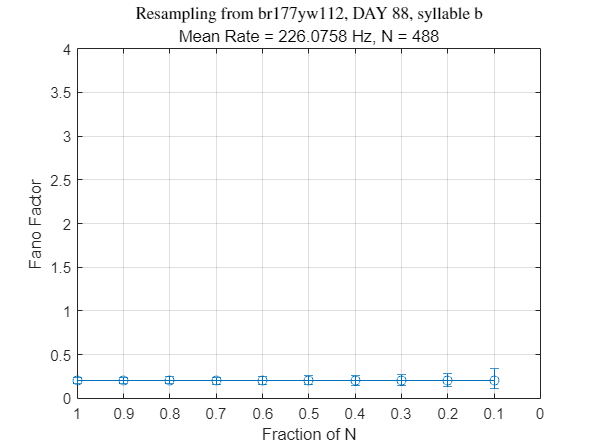

    {'br177yw112_c_day88'}



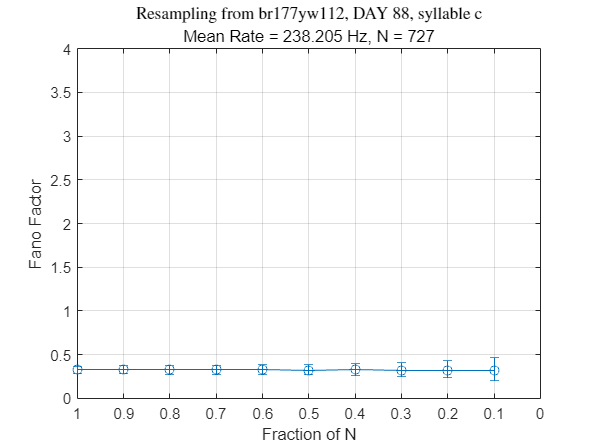

    {'br177yw112_d_day88'}



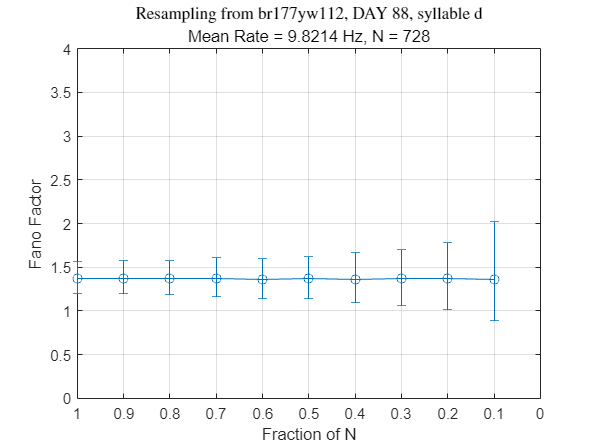

    {'br177yw112_g_day88'}



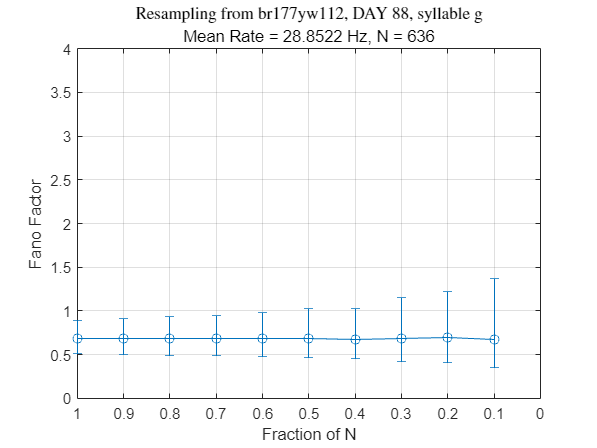

    {'br177yw112_h_day88'}



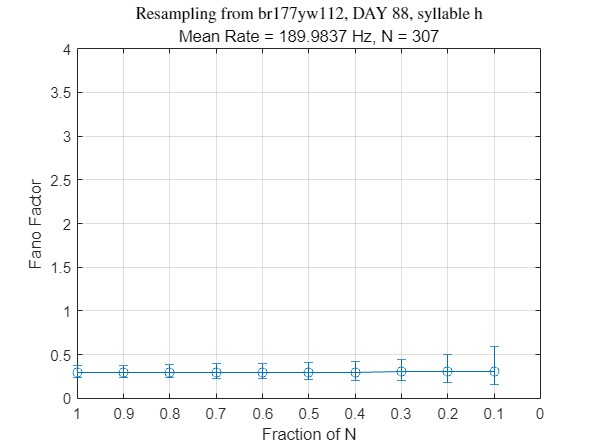

    {'br177yw112_j_day88'}



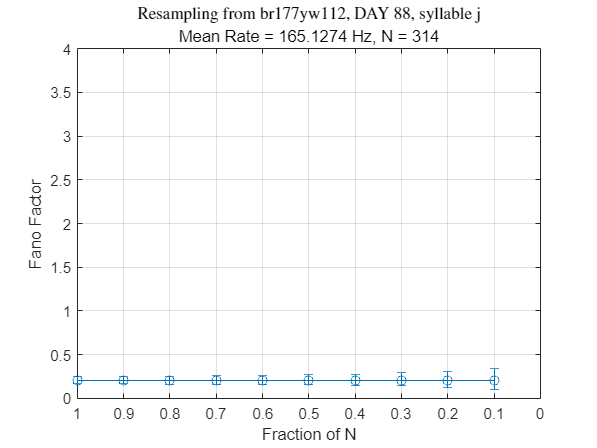

    {'br177yw112_k_day88'}



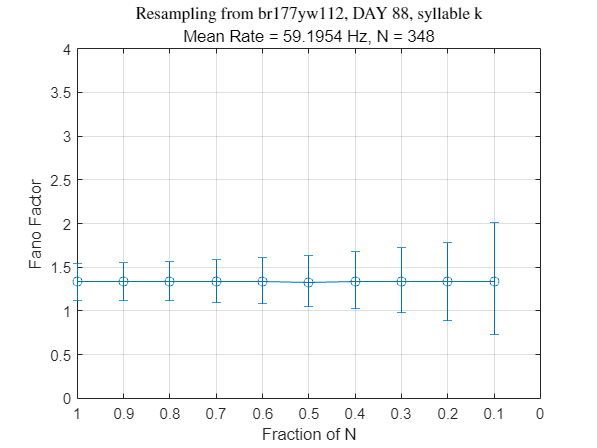

    {'br177yw112_r_day88'}



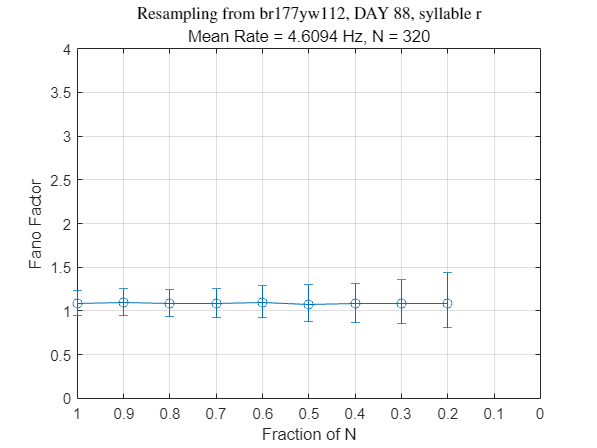

    {'br177yw112_m_day88'}



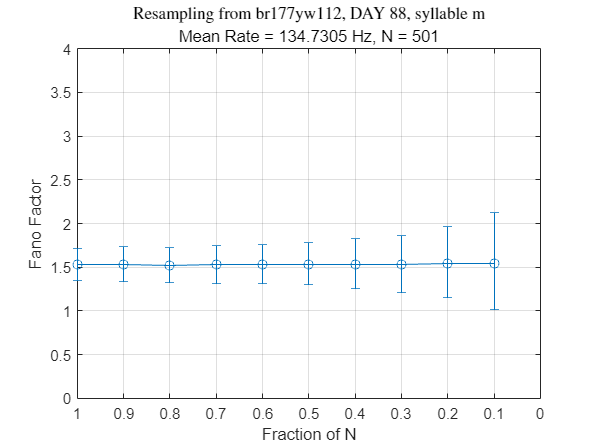

    {'br173gr56_b_day78'}



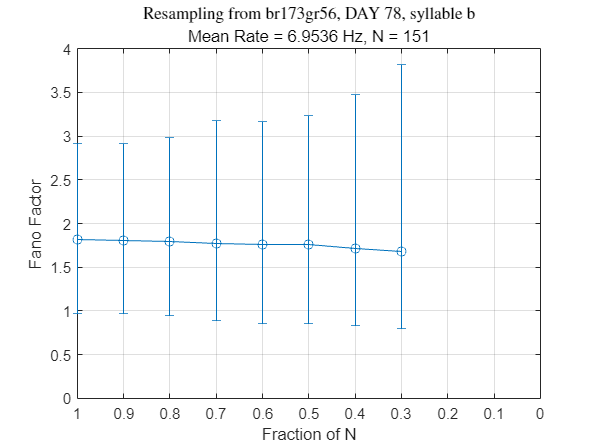

    {'br173gr56_c_day78'}



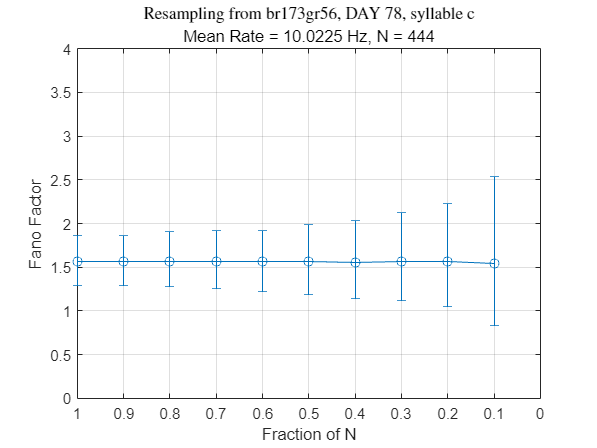

    {'br173gr56_f_day78'}



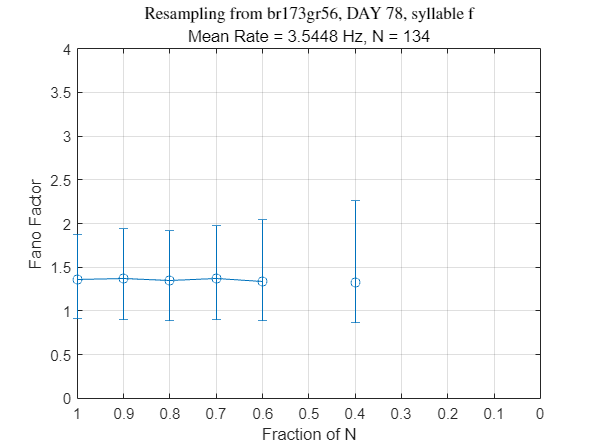

    {'br173gr56_g_day78'}



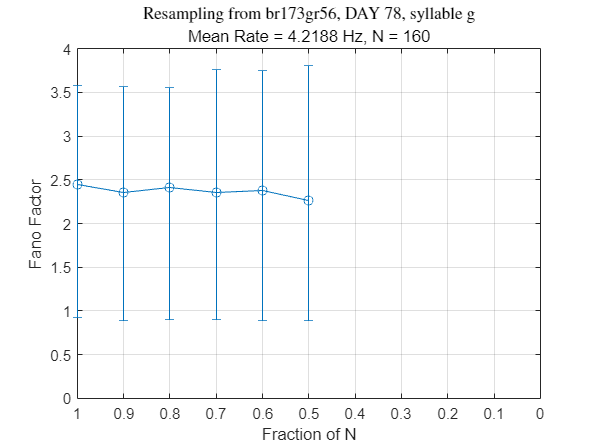

    {'br173gr56_h_day78'}



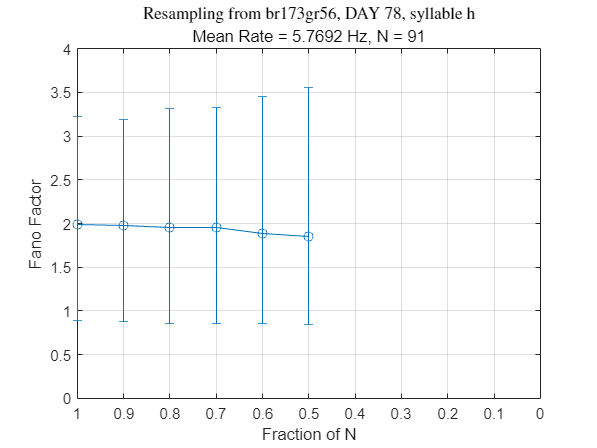

    {'br173gr56_j_day78'}



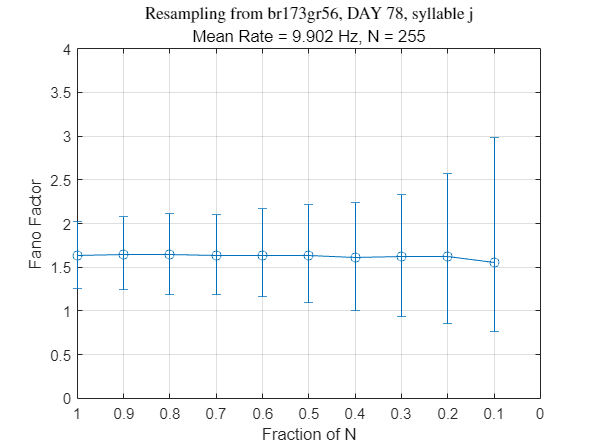

    {'br173gr56_k_day78'}



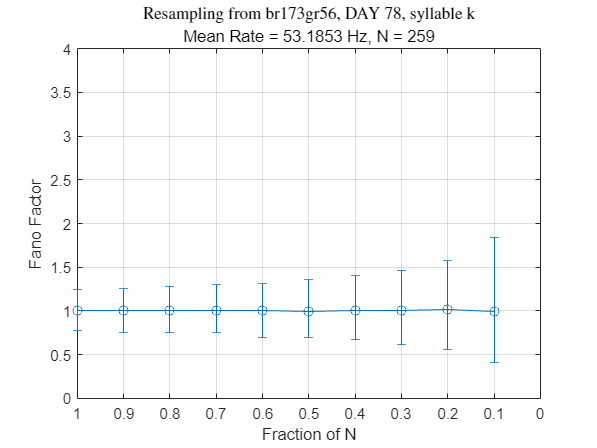

    {'br173gr56_p_day78'}



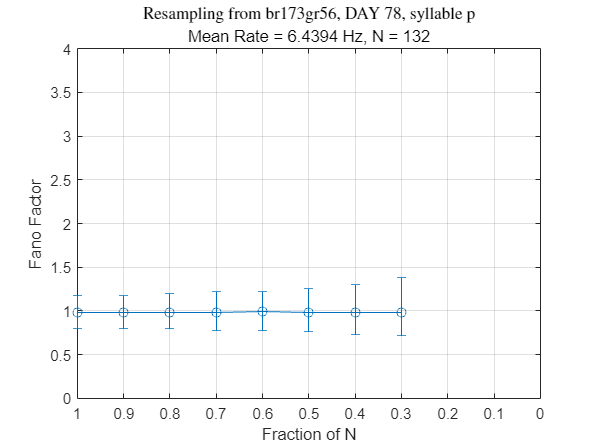

    {'br173gr56_q_day78'}



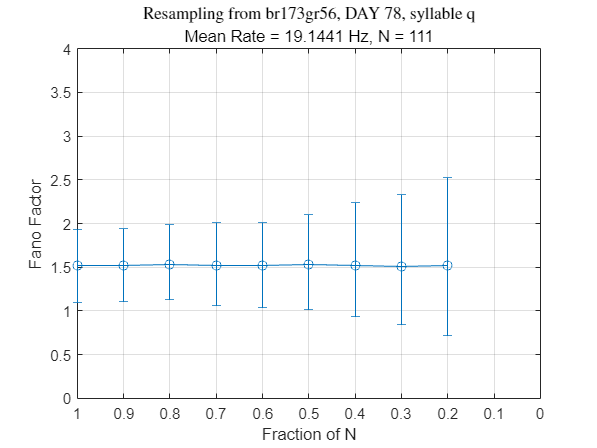

    {'br173gr56_r_day78'}



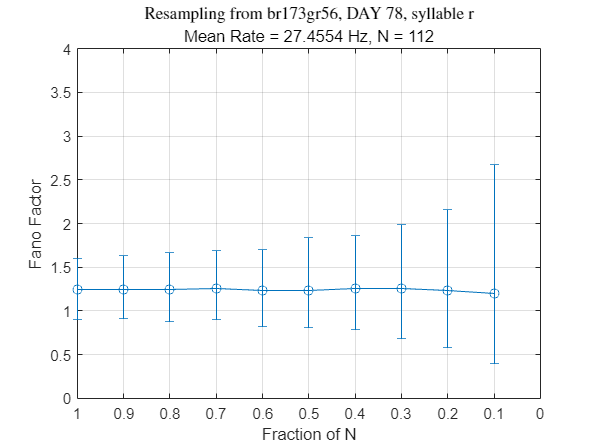

    {'br173gr56_s_day78'}



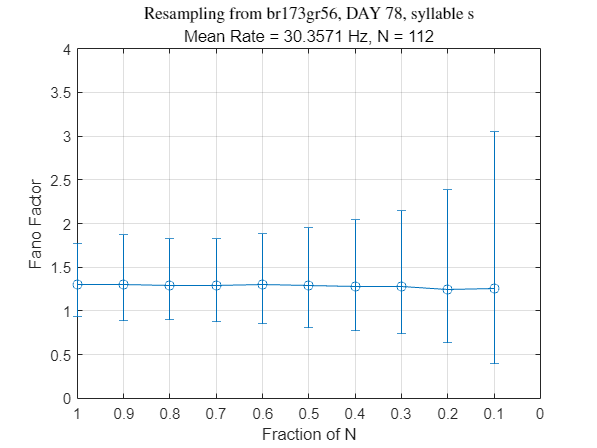

    {'br173gr56_b_day801'}



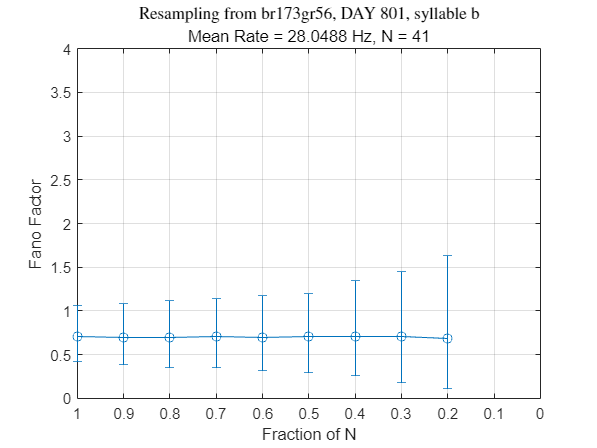

    {'br173gr56_c_day801'}



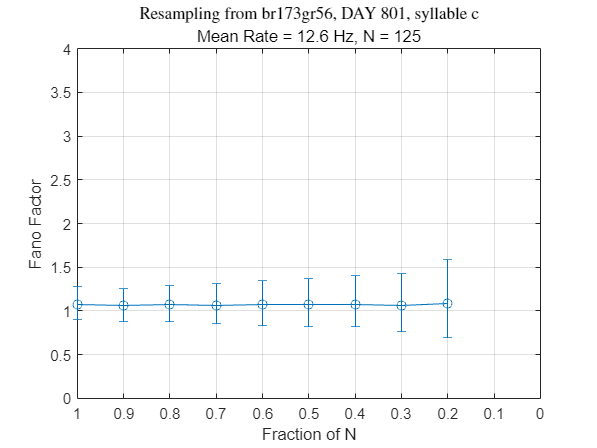

    {'br173gr56_f_day801'}



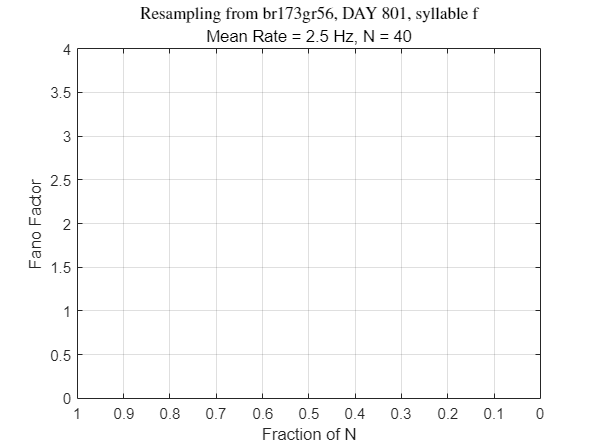

    {'br173gr56_g_day801'}



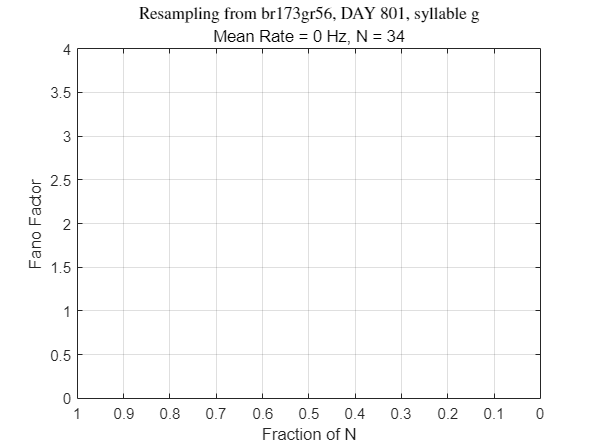

    {'br173gr56_h_day801'}



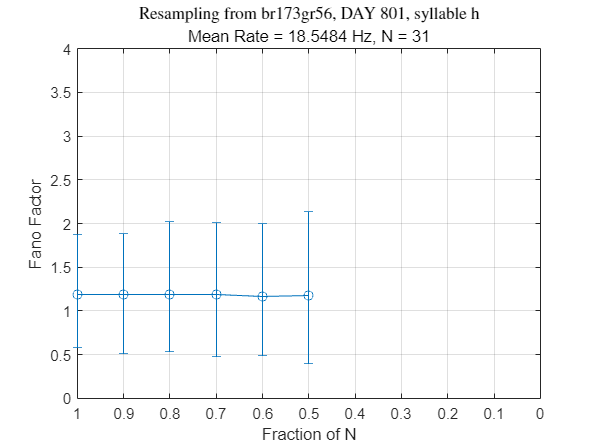

    {'br173gr56_j_day801'}



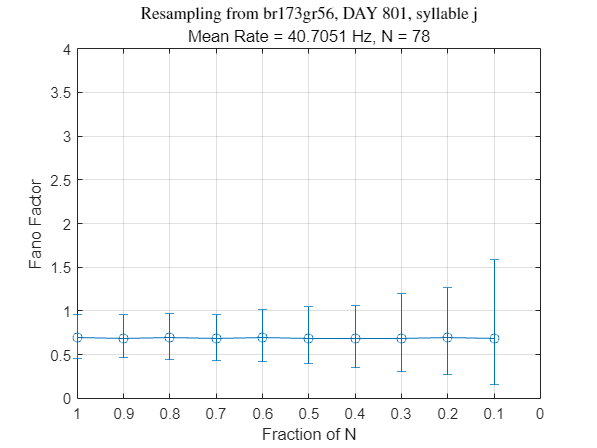

    {'br173gr56_k_day801'}



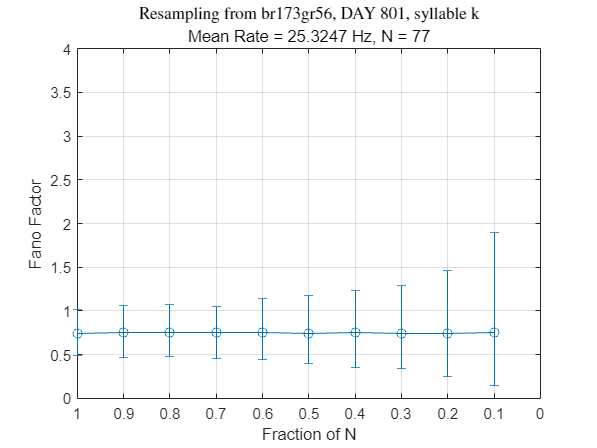

    {'br173gr56_p_day801'}



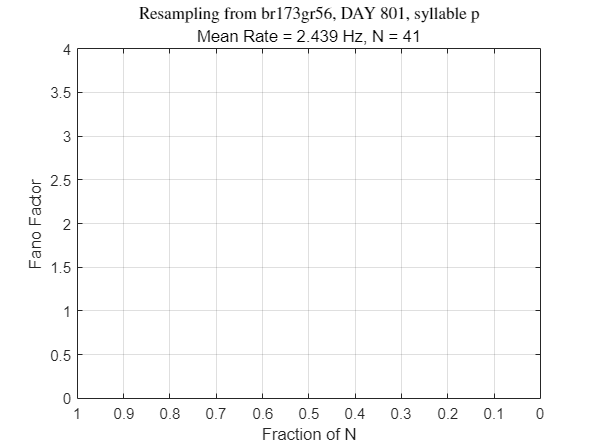

    {'br173gr56_q_day801'}



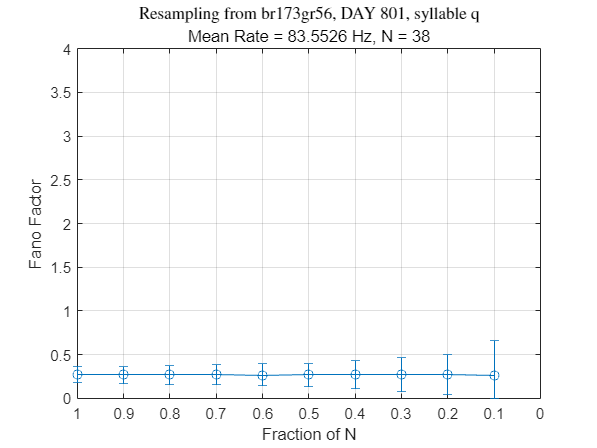

    {'br173gr56_s_day801'}



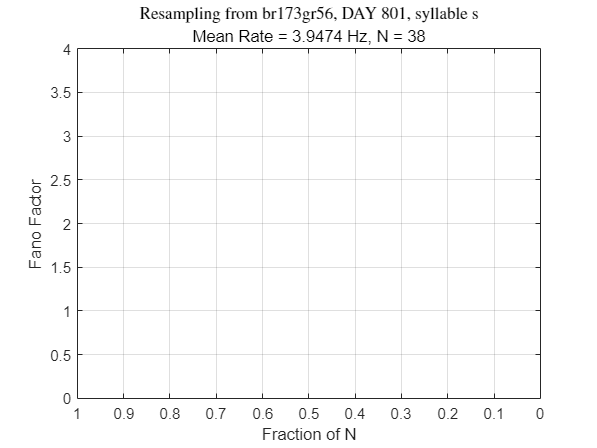

    {'br173gr56_c_day802'}



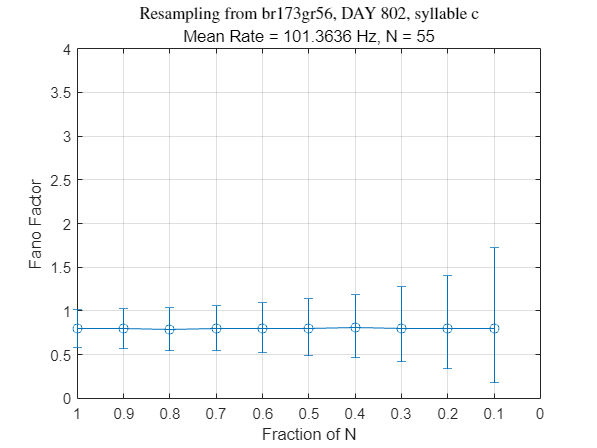

    {'br173gr56_j_day802'}



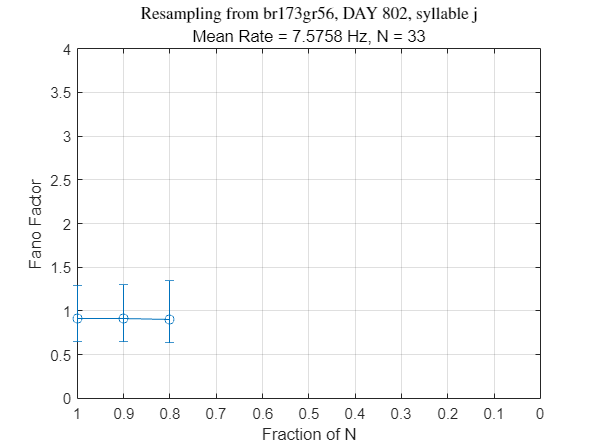

    {'br173gr56_k_day802'}



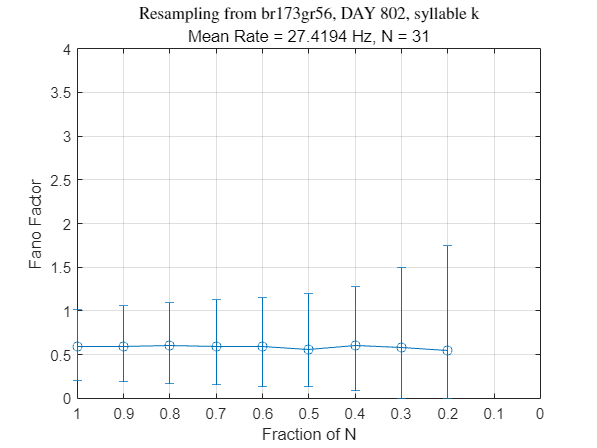

    {'br173gr56_b_day803'}



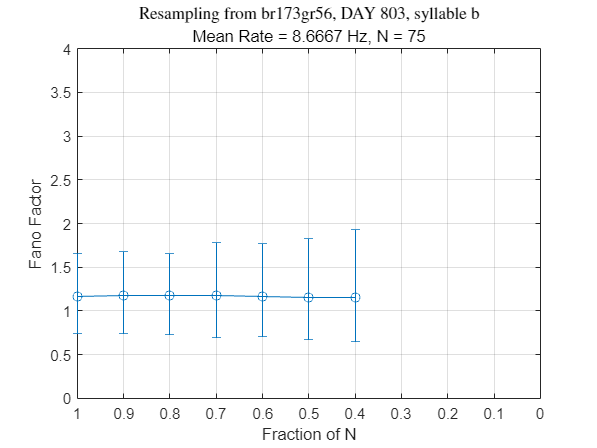

    {'br173gr56_c_day803'}



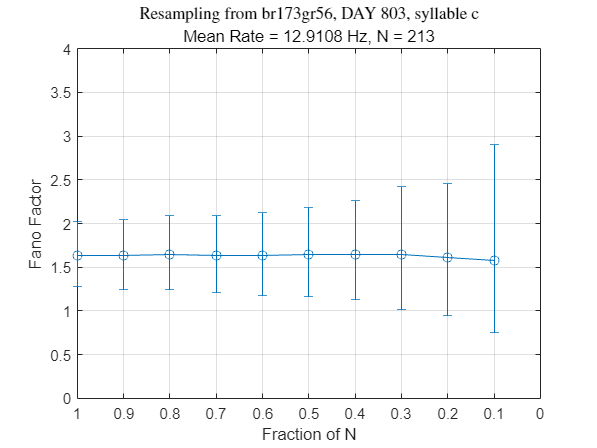

    {'br173gr56_f_day803'}



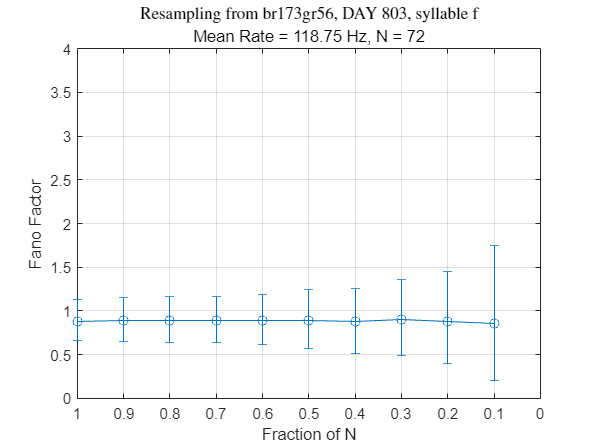

    {'br173gr56_g_day803'}



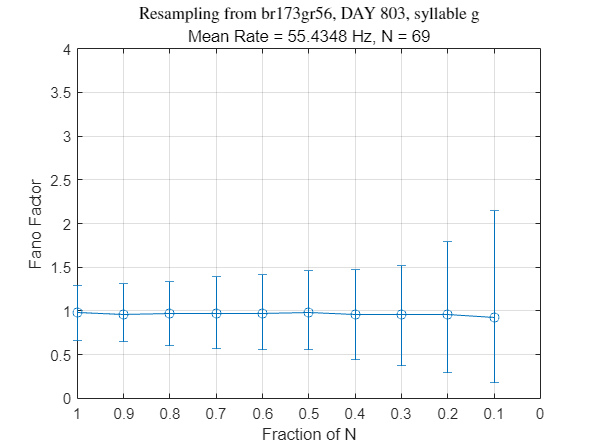

    {'br173gr56_h_day803'}



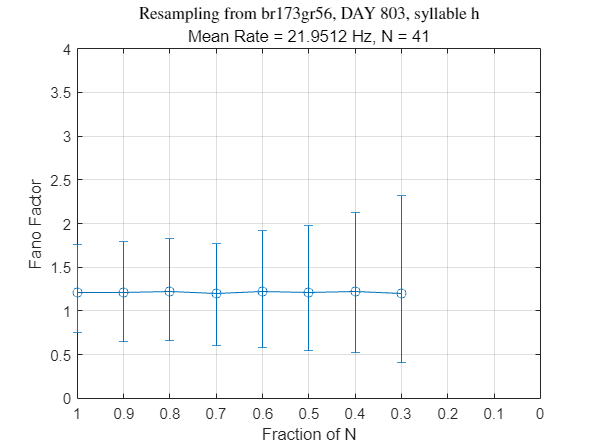

    {'br173gr56_j_day803'}



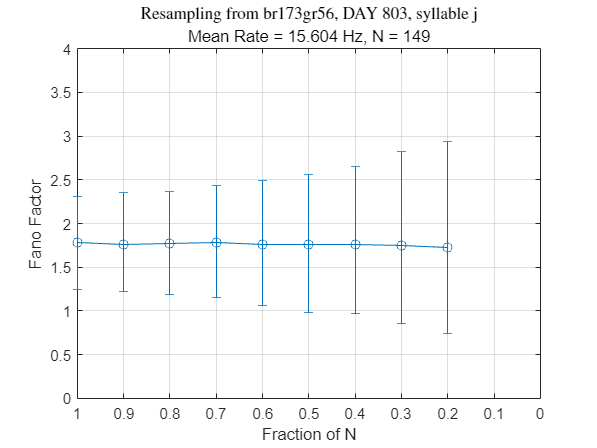

    {'br173gr56_k_day803'}



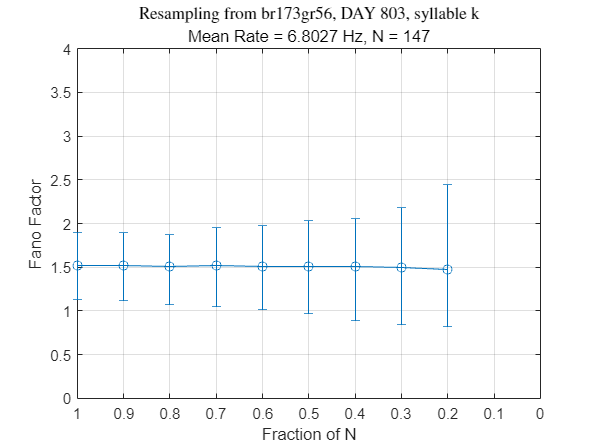

    {'br173gr56_p_day803'}



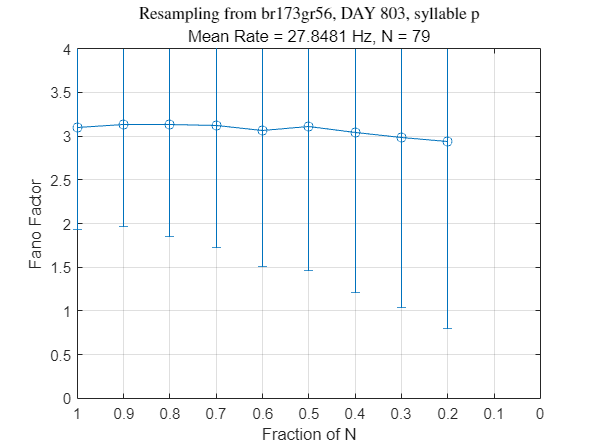

    {'br173gr56_q_day803'}



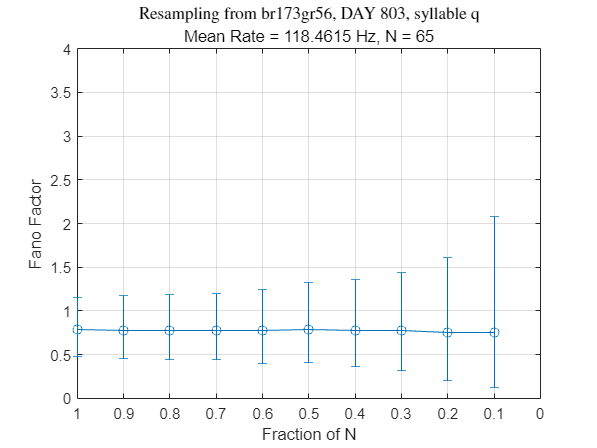

    {'br173gr56_s_day803'}



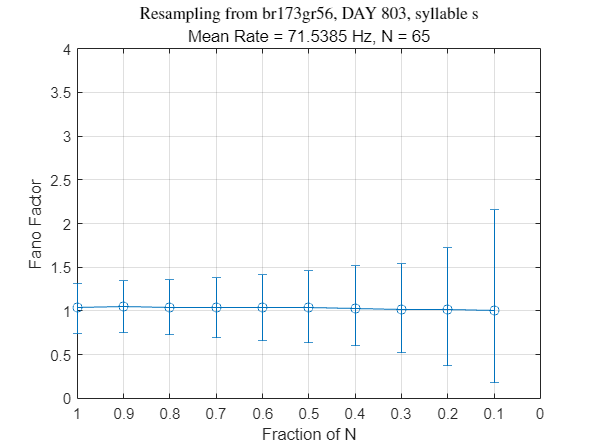

    {'br173gr56_b_day811'}



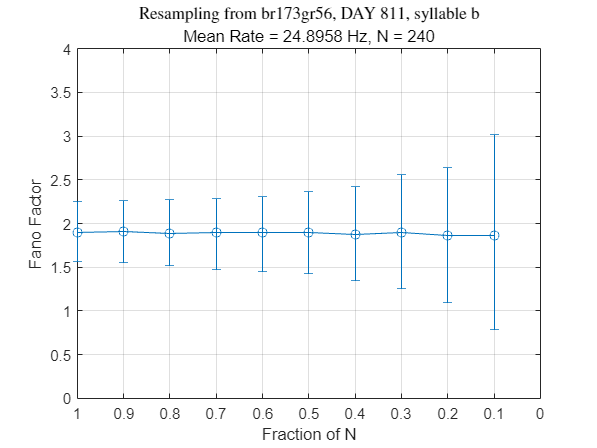

    {'br173gr56_c_day811'}



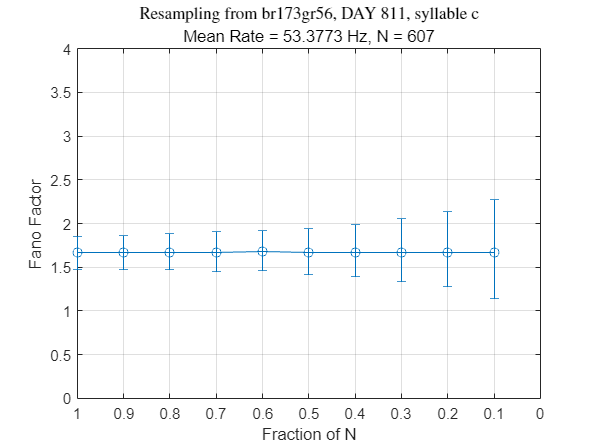

    {'br173gr56_f_day811'}



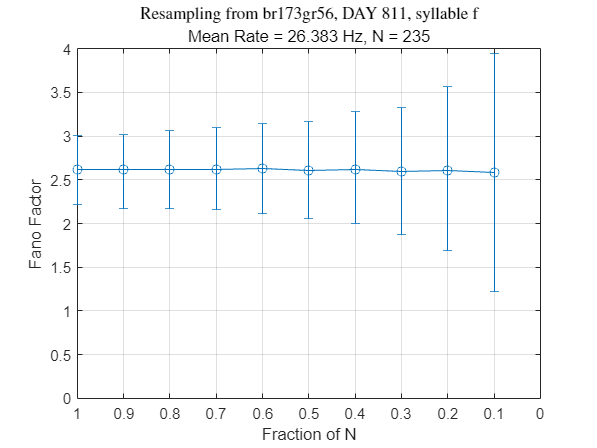

    {'br173gr56_g_day811'}



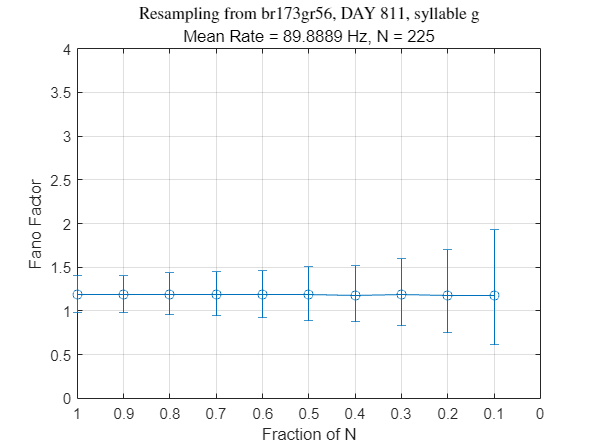

    {'br173gr56_h_day811'}



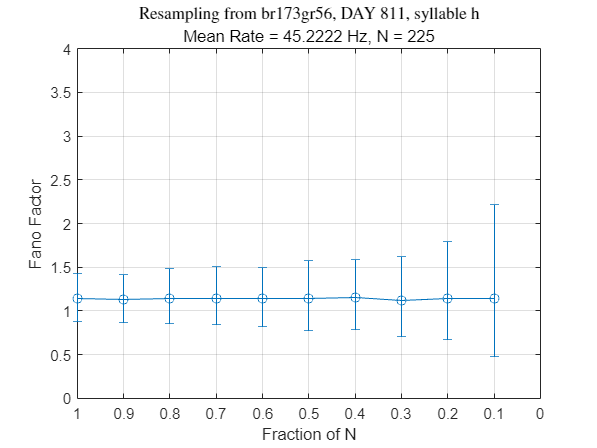

    {'br173gr56_j_day811'}



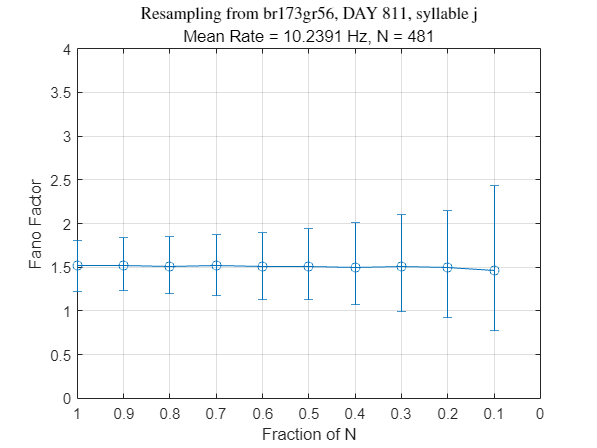

    {'br173gr56_k_day811'}



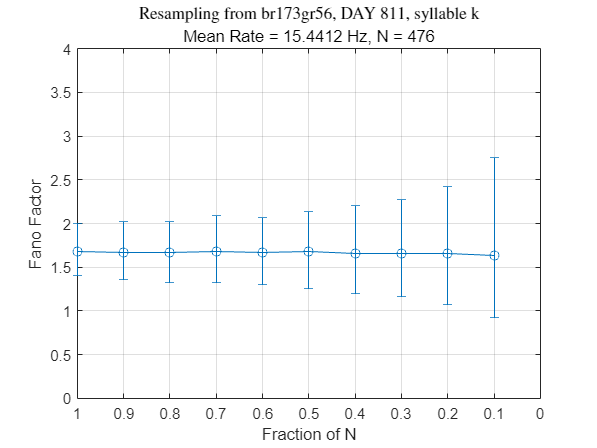

    {'br173gr56_p_day811'}



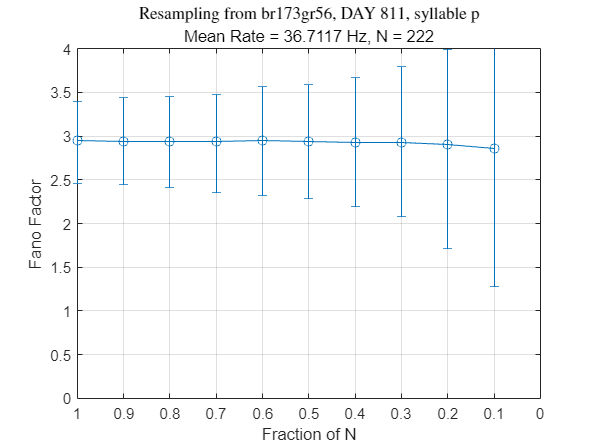

    {'br173gr56_q_day811'}



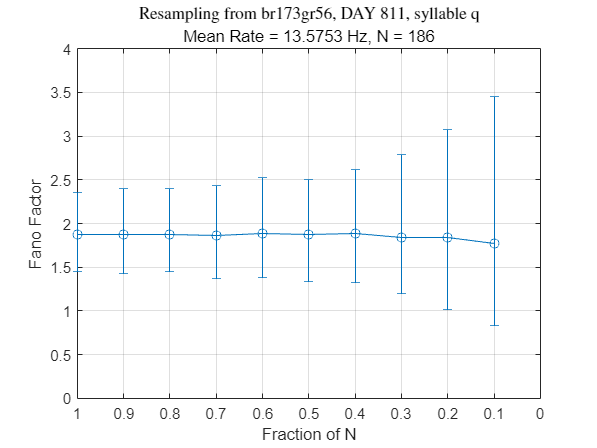

    {'br173gr56_r_day811'}



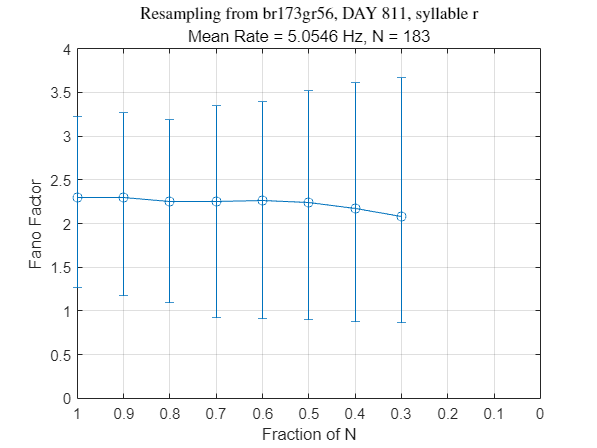

    {'br173gr56_s_day811'}



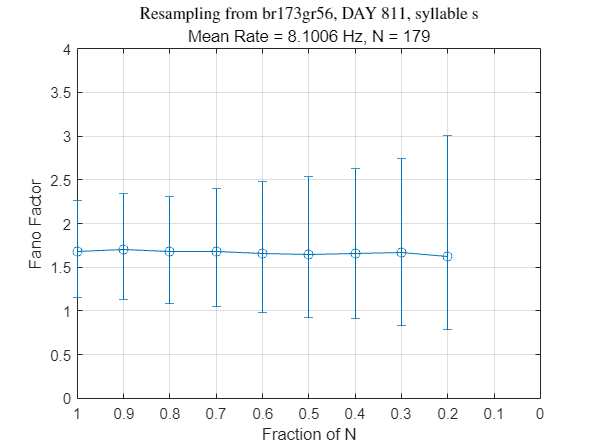

    {'br173gr56_b_day812'}



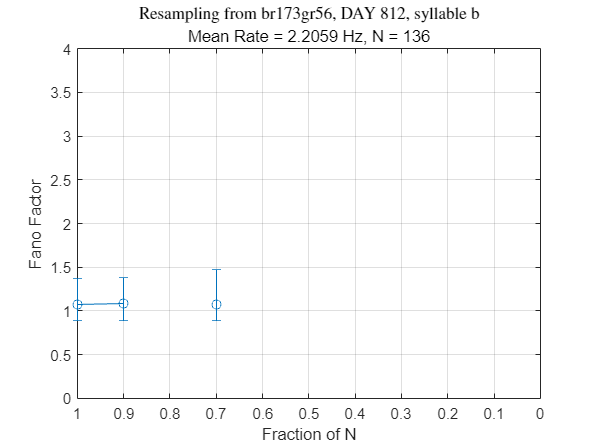

    {'br173gr56_c_day812'}



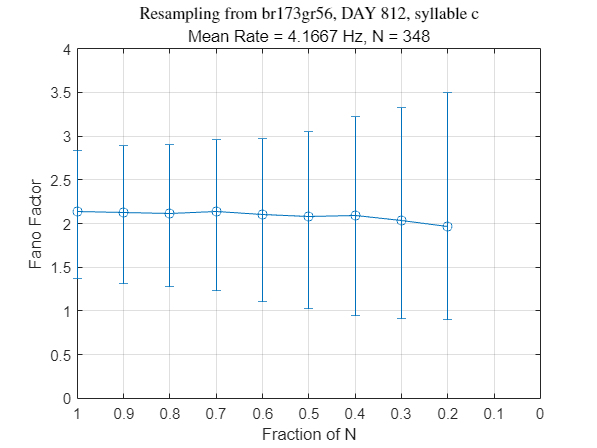

    {'br173gr56_f_day812'}



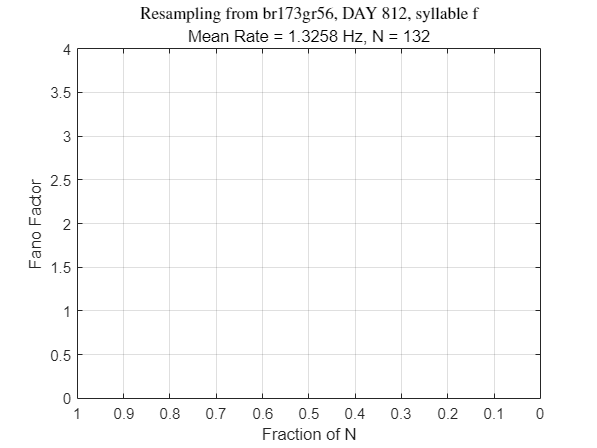

    {'br173gr56_g_day812'}



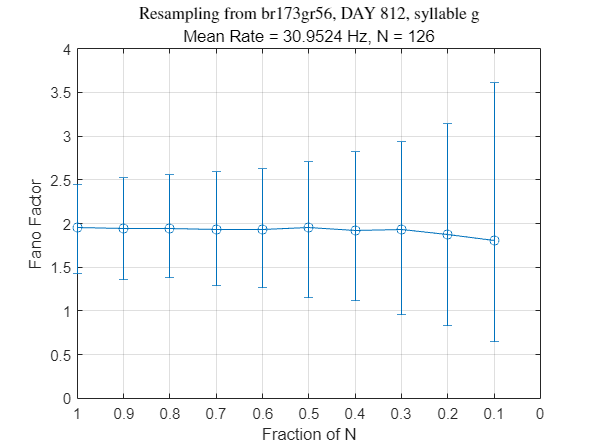

    {'br173gr56_h_day812'}



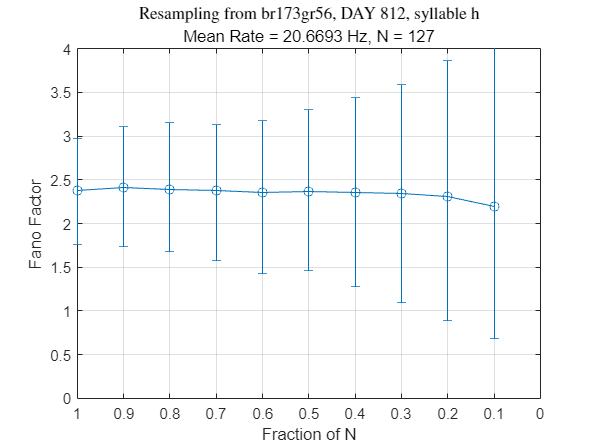

    {'br173gr56_j_day812'}



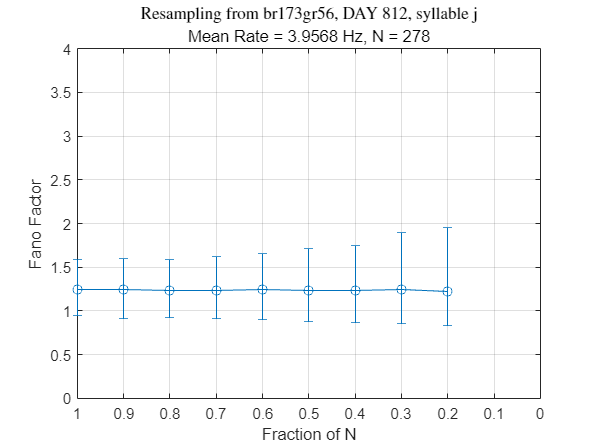

    {'br173gr56_k_day812'}



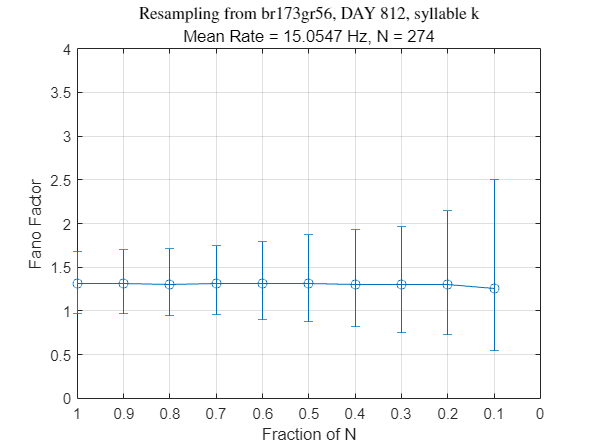

    {'br173gr56_p_day812'}



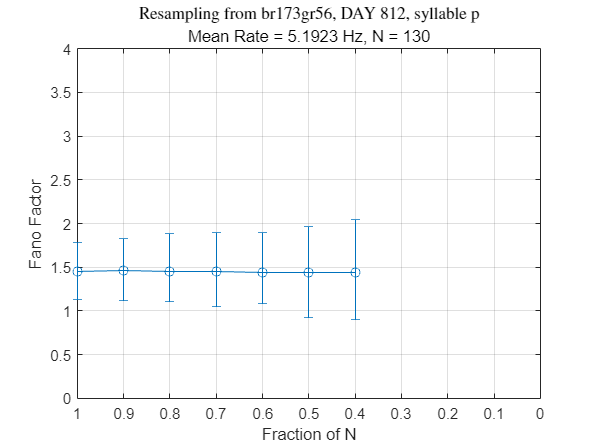

    {'br173gr56_q_day812'}



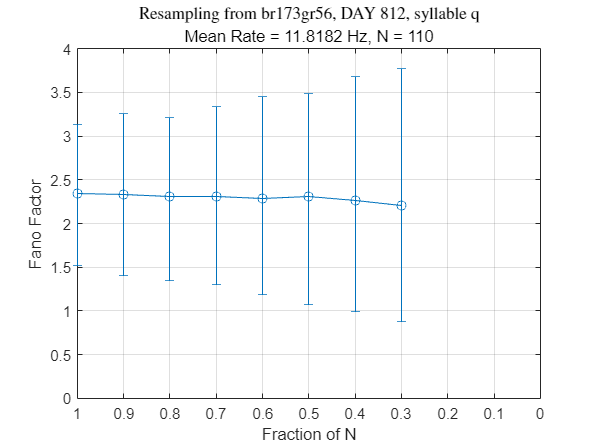

    {'br173gr56_r_day812'}



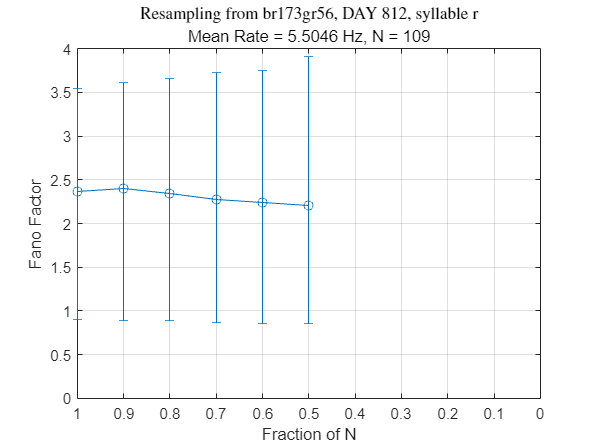

    {'br173gr56_s_day812'}



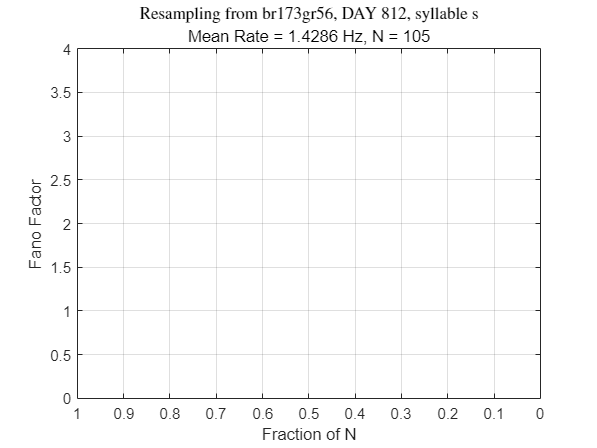

    {'br173gr56_b_day153'}



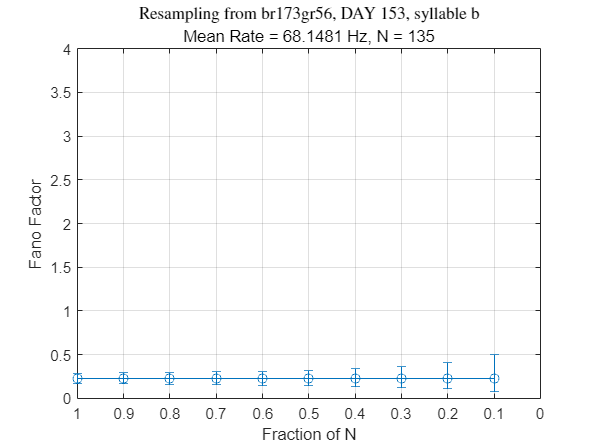

    {'br173gr56_c_day153'}



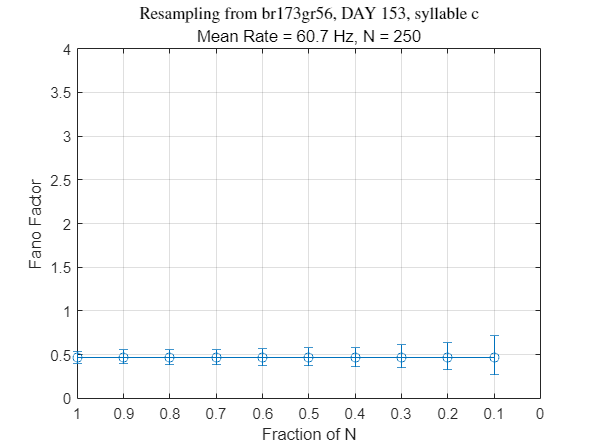

    {'br173gr56_f_day153'}



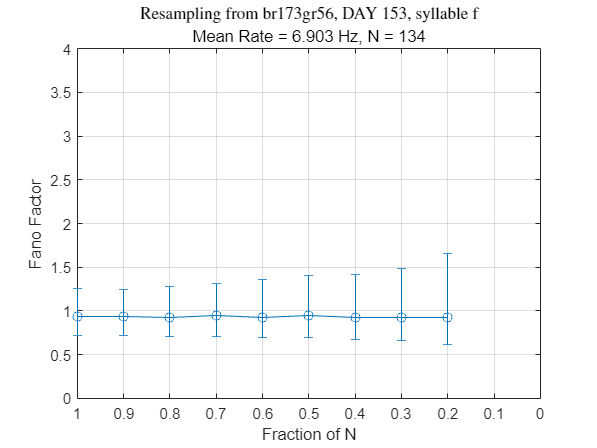

    {'br173gr56_g_day153'}



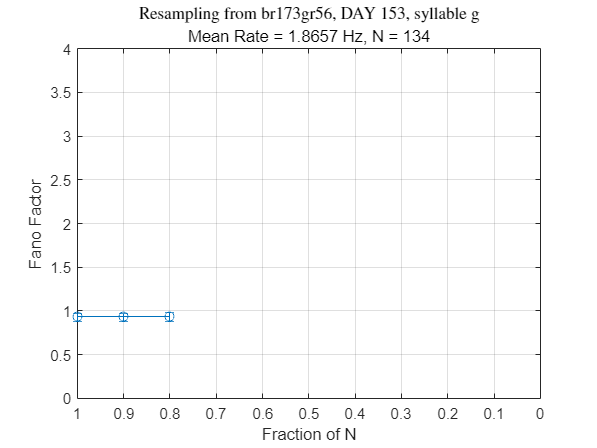

    {'br173gr56_h_day153'}



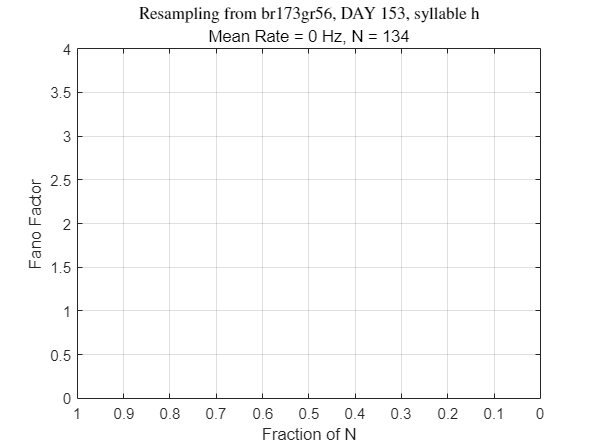

    {'br173gr56_j_day153'}



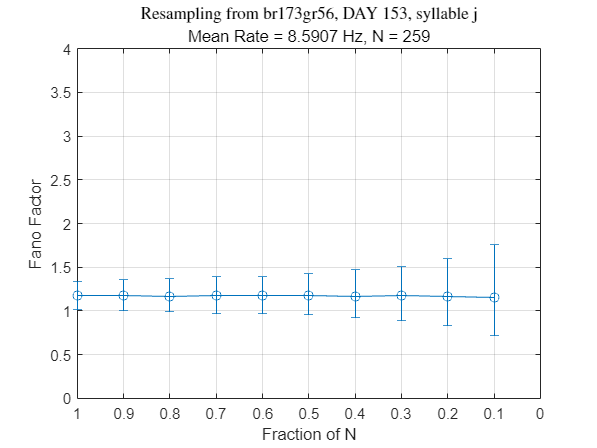

    {'br173gr56_k_day153'}



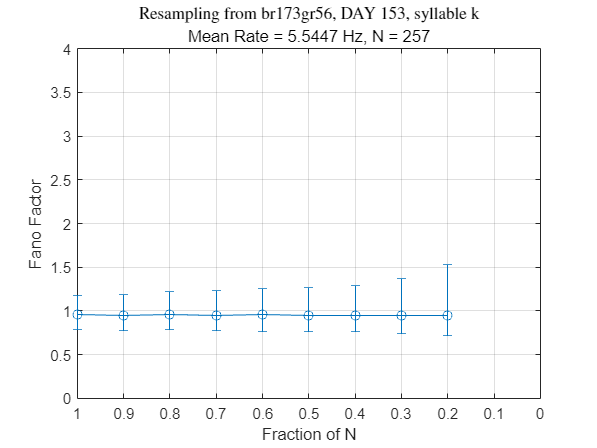

    {'br173gr56_p_day153'}



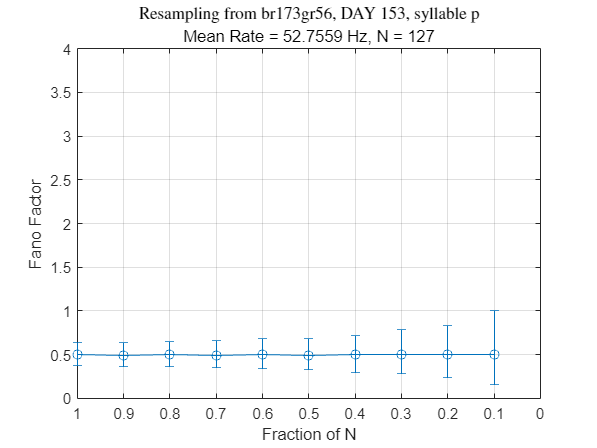

    {'br173gr56_q_day153'}



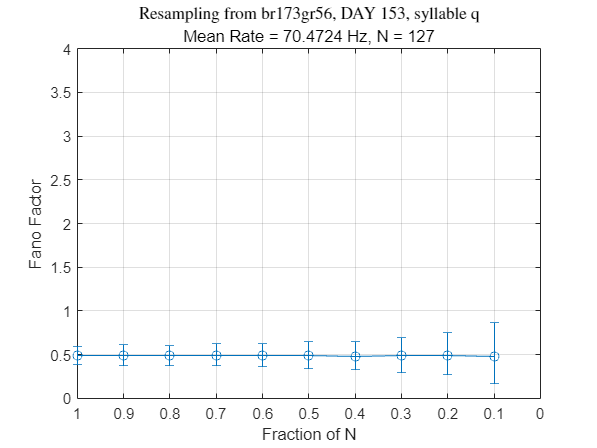

motor_window = 0.04; %sec
juv_params.preonset = 0.01;
juv_params.postonset = 0.03;
juv_params.minTrials = 25;
juv_params.minSpikes = 0;

% juv_early = analy_motor_win(allCases,juv_params);
spikeStats = analy_motor_win(allCases,juv_params);


clearvars juv_params getTrials

## PLOT FANO FACTOR 

Plot FF for all syllable cases across time. 

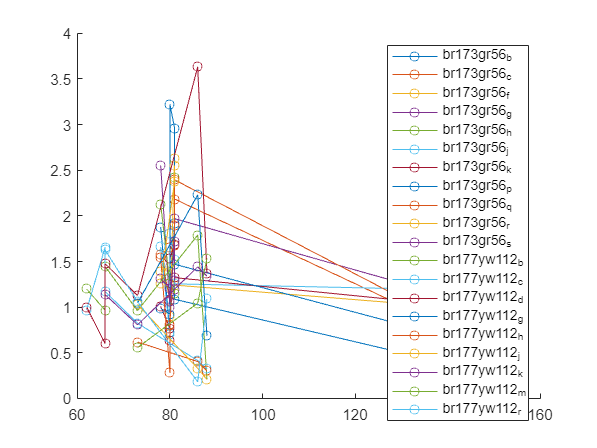

% figct = figct +1;
% figure(figct);clf;hold on
fontname = 'Franklin Gothic Heavy';

% extract the fano factors for distinct syllables
    filenames = spikeStats.casenames;
    % Initialize an empty cell array for the extracted parts
    extractedParts = cell(size(filenames));

    for i = 1:length(filenames)
        filename = filenames{i};
        
        % Find indices of underscores in the filename
        underscoreIndices = strfind(filename, '_');
        extractedParts{i} = filename(1:underscoreIndices(2)-1);
        case_days(i) = str2double(filename(underscoreIndices(2)+4:end));
    end

    % change neuron ID to days
    case_days(case_days == 661 | case_days == 662) = 66; 
    case_days(case_days == 801 | case_days == 802 | case_days == 803) = 80;
    case_days(case_days == 811 | case_days == 812) = 81;
    
    % Find unique values and their first index of occurrence
    [uniqueParts, ~, idxUnique] = unique(extractedParts);
    
    % idxUnique now holds indices of extractedParts that map back to the original list of filenames
    % To find the unique indices corresponding to the original list of filenames:
    uniqueIndices = arrayfun(@(x) find(idxUnique == x, 1, 'first'), 1:length(uniqueParts));

    % for each unique syllable, create vectors of the days and the
    % corresponding fano factors
    uniqueSyl = uniqueParts;
    for ii = 1:length(uniqueSyl)
        uniqueSyl(ii);
        syl_idx = find(idxUnique == ii);
        syl_ffs{ii} = spikeStats.fano_factor(syl_idx);
        syl_casenames{ii} = spikeStats.casenames(syl_idx);
        syl_days{ii} = case_days(syl_idx);
    end

% Plot the fano factor of a distinct syllable over time
figure; hold on
for j = 1:length(uniqueSyl)
    plot(syl_days{j}, syl_ffs{j},'-o')
end
legend(uniqueSyl)

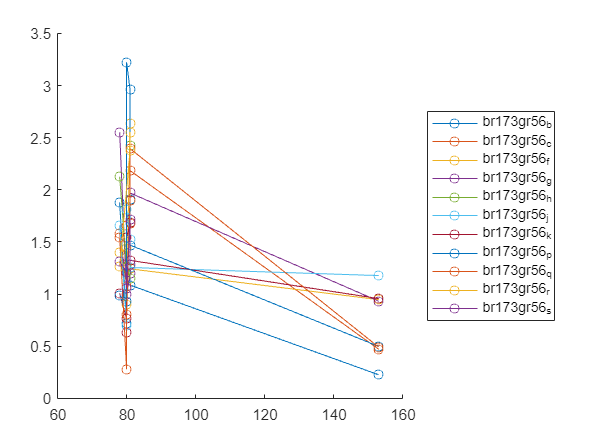


% plot for each bird
figure; hold on
which = 1:11;
for j = which
    plot(syl_days{j}, syl_ffs{j},'-o')
end
legend(uniqueSyl(which),Location="eastoutside")

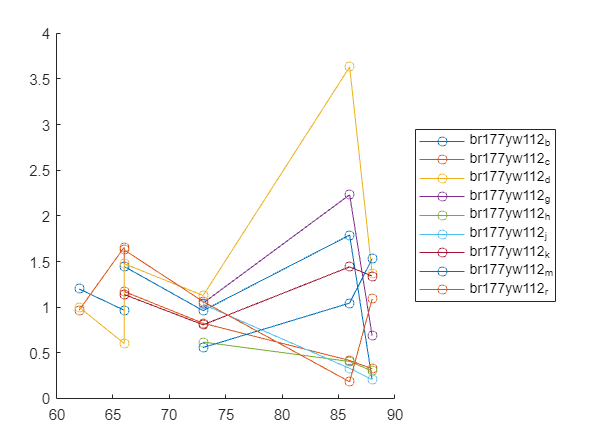


figure; hold on
which = 12:20;
for j = which
    plot(syl_days{j}, syl_ffs{j},'-o')
end
legend(uniqueSyl(which),Location = "eastoutside")


% PLOT for individual syllables
% for j = 1:length(uniqueSyl)
%     figure; plot(syl_days{j}, syl_ffs{j},'-o')
%     title(uniqueSyl(j))
%     xlim([62 160])
%     ylim([0 4])
% end

Just plot for syllables c/r

% find the indices for c and r
idx_c = find(strcmp('br177yw112_c',uniqueSyl))

idx_c = 13

uniqueSyl(idx_c)

ans = 1×1 cell array
    {'br177yw112_c'}


idx_r = find(strcmp('br177yw112_r',uniqueSyl))

idx_r = 20

uniqueSyl(idx_r)

ans = 1×1 cell array
    {'br177yw112_r'}


idx_cr = [idx_c idx_r]

idx_cr =     13    20



    for jj = 1:2
        ii = idx_cr(jj);
        uniqueSyl(ii);
        syl_idx = find(idxUnique == ii);
        syl_counts{jj} = spikeStats.spike_counts(syl_idx);
        syl_ffs{jj} = spikeStats.fano_factor(syl_idx);
        syl_casenames{jj} = spikeStats.casenames(syl_idx);
        syl_days{jj} = case_days(syl_idx);
    end

ff_cr = [syl_ffs{1}(1) ff_cr]
% recalculate ff for day 
'br177yw112_c_day62'
'br177yw112_c_day661'
'br177yw112_c_day662'
'br177yw112_c_day73'
'br177yw112_c_day86'
'br177yw112_c_day88'
0.967923280423281
1.65694581280788
1.17152103559871
0.823384746174397
0.415685685584626
0.325432759819940

'br177yw112_r_day662'
'br177yw112_r_day73'
'br177yw112_r_day86'
'br177yw112_r_day88'
1.62719298245614
1.06091846298032
0.181992770604048
1.09021837309389

days = [62 66 73 86 88]; 
ff_cr = []

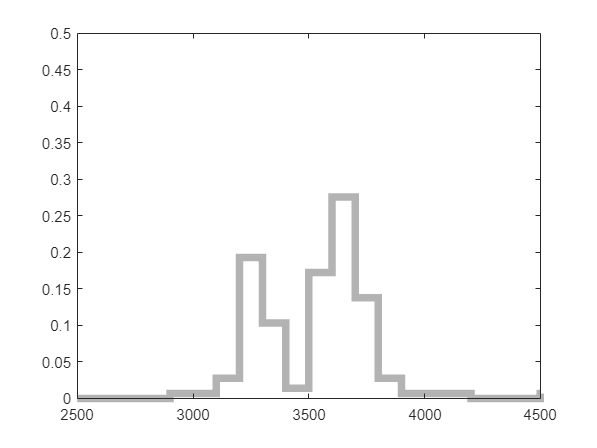

yclr = [.7 .7 .7];
cclr = '#B8CFEB';
rclr = '#4DAF4D';
linewidth = 5;

figure;c62=histogram(allCases.br177yw112_c_day62.weighted_avg_pitch,BinWidth=100,Normalization='probability',DisplayStyle='stairs'); xlim([2500 4500]); ylim([0 0.5])
c62.EdgeColor = [.7 .7 .7]; c62.LineWidth = linewidth;

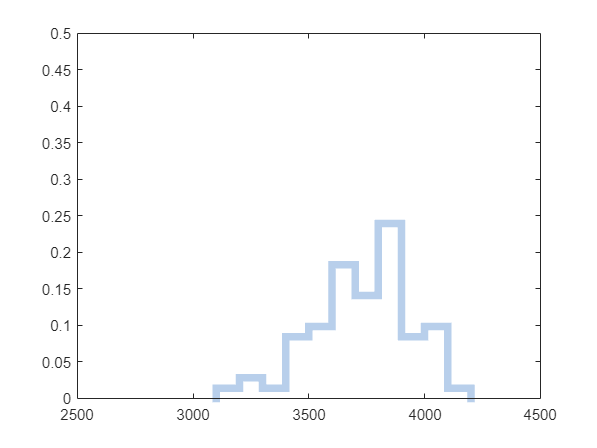


figure;c661=histogram(allCases.br177yw112_c_day661.weighted_avg_pitch,BinWidth=100,Normalization='probability',DisplayStyle='stairs'); xlim([2500 4500]); ylim([0 0.5])
c661.EdgeColor = cclr; c661.LineWidth = 5;
hold on; r661=histogram(allCases.br177yw112_r_day661.weighted_avg_pitch,BinWidth=100,Normalization='probability',DisplayStyle='stairs'); xlim([2500 4500]); ylim([0 0.5])
r661.EdgeColor = rclr; r661.LineWidth = linewidth;

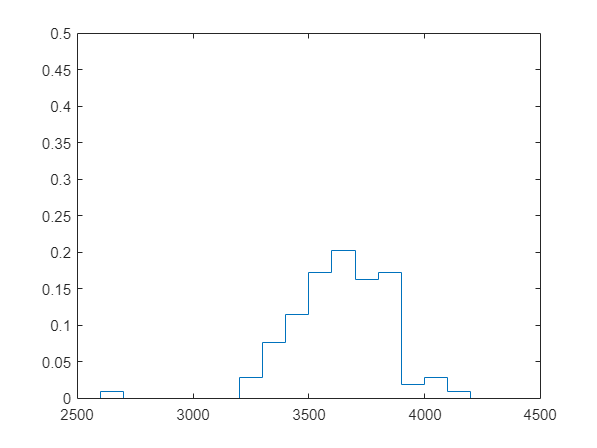


figure;c662=histogram(allCases.br177yw112_c_day662.weighted_avg_pitch,BinWidth=100,Normalization='probability',DisplayStyle='stairs'); xlim([2500 4500]); ylim([0 0.5])
hold on; histogram(allCases.br177yw112_r_day662.weighted_avg_pitch,BinWidth=100,Normalization='probability',DisplayStyle='stairs'); xlim([2500 4500]); ylim([0 0.5])

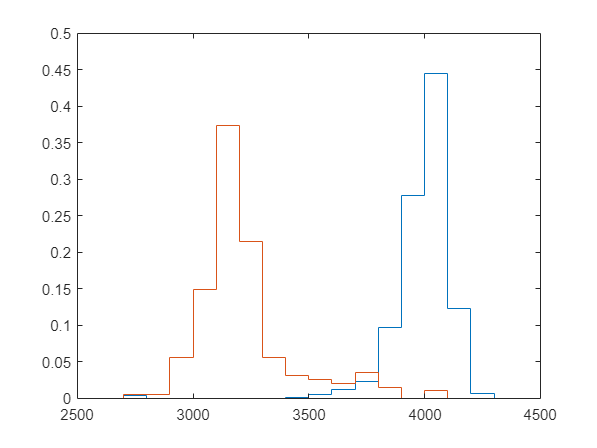

r662.EdgeColor = rclr; r662.LineWidth = linewidth;

figure;p73=histogram(allCases.br177yw112_c_day73.weighted_avg_pitch,BinWidth=100,Normalization='probability',DisplayStyle='stairs'); xlim([2500 4500]); ylim([0 0.5])
hold on; histogram(allCases.br177yw112_r_day73.weighted_avg_pitch,BinWidth=100,Normalization='probability',DisplayStyle='stairs'); xlim([2500 4500]); ylim([0 0.5])

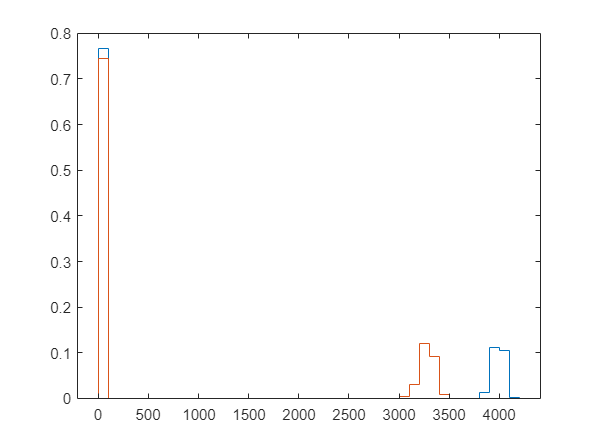


figure;p86=histogram(allCases.br177yw112_c_day86.weighted_avg_pitch,BinWidth=100,Normalization='probability',DisplayStyle='stairs'); 
% xlim([2500 4500]); ylim([0 0.5])
hold on; histogram(allCases.br177yw112_r_day86.weighted_avg_pitch,BinWidth=100,Normalization='probability',DisplayStyle='stairs'); 

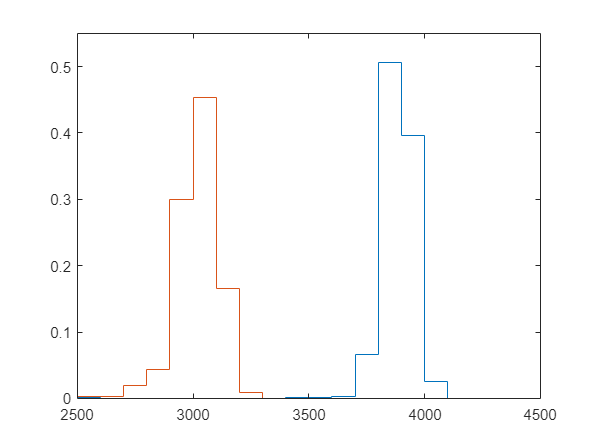

% xlim([2500 4500]); ylim([0 0.5])

figure;p88=histogram(allCases.br177yw112_c_day88.weighted_avg_pitch,BinWidth=100,Normalization='probability',DisplayStyle='stairs'); xlim([2500 4500]); ylim([0 0.5])
hold on; histogram(allCases.br177yw112_r_day88.weighted_avg_pitch,BinWidth=100,Normalization='probability',DisplayStyle='stairs'); xlim([2500 4500]); ylim([0 0.55])

xtix =         3000        4000


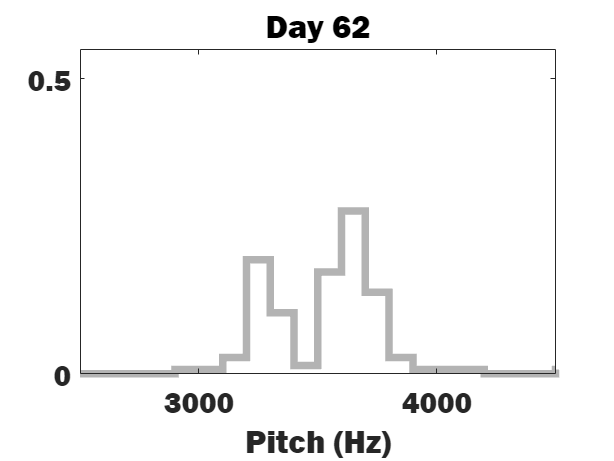

rFieldName = 'br177yw112_r_day62.weighted_avg_pitch'

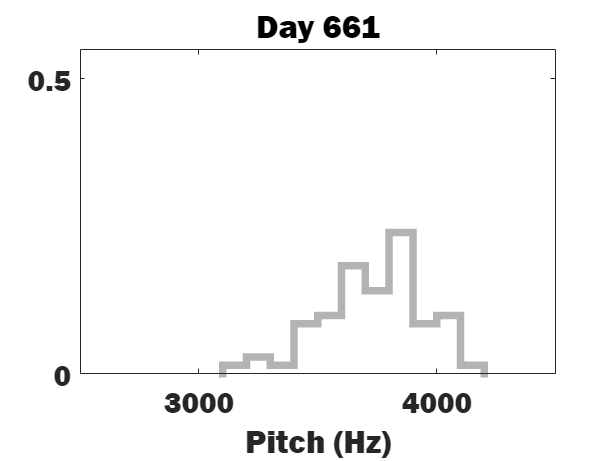

rFieldName = 'br177yw112_r_day661.weighted_avg_pitch'

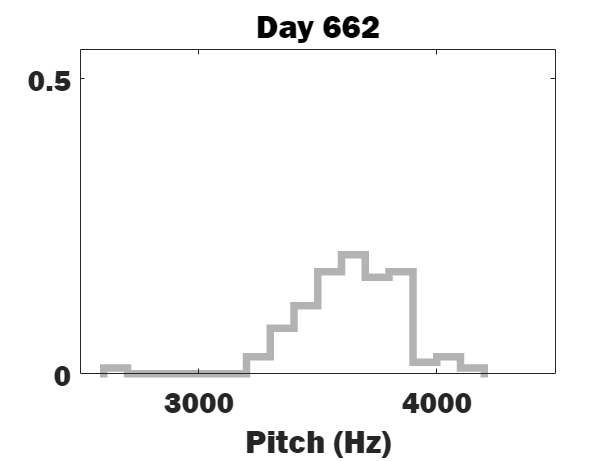

rFieldName = 'br177yw112_r_day662.weighted_avg_pitch'

rFieldName = 'br177yw112_r_day73.weighted_avg_pitch'

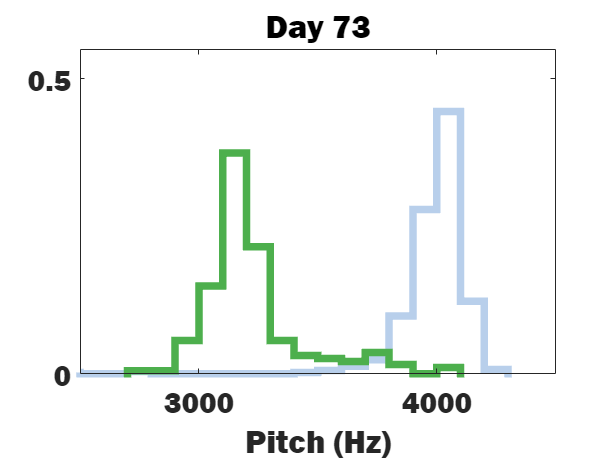

rFieldName = 'br177yw112_r_day86.weighted_avg_pitch'

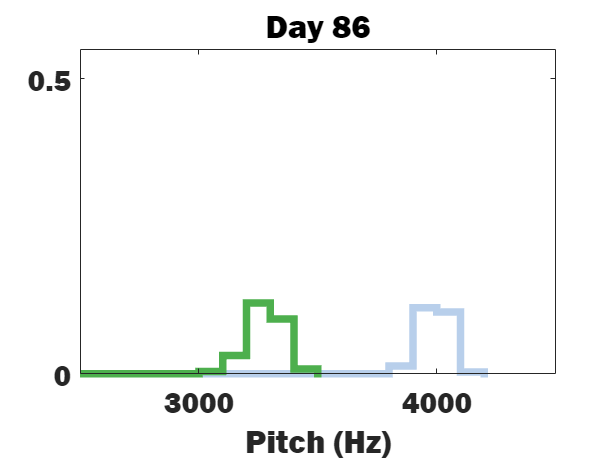

rFieldName = 'br177yw112_r_day88.weighted_avg_pitch'

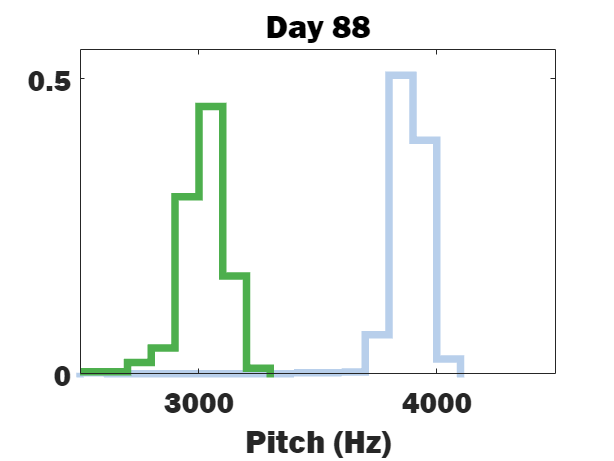

% Colors and linewidth
yclr = [.7 .7 .7];
cclr = '#B8CFEB';
rclr = '#4DAF4D';
linewidth = 5;

% Days to plot
days = [62, 661, 662, 73, 86, 88];

% Call the function with the appropriate parameters
plotHistograms(allCases, days, yclr, cclr, rclr, linewidth);

## Run Spike Stats Analysis - CHANGE MOTOR WINDOW

motor_window = 0.06; %sec
juv_params.preonset = 0.04;
juv_params.postonset = 0.02;
juv_params.minTrials = 25;
juv_params.minSpikes = 1;

% juv_early = analy_motor_win(allCases,juv_params);
spikeStats = analy_motor_win(allCases,juv_params);

plotflag = 0

    {'br177yw112_b_day62'}

    {'br177yw112_c_day62'}

    {'br177yw112_d_day62'}

    {'br177yw112_b_day661'}

    {'br177yw112_c_day661'}

    {'br177yw112_d_day661'}

    {'br177yw112_b_day662'}

    {'br177yw112_c_day662'}

    {'br177yw112_d_day662'}

    {'br177yw112_k_day662'}

    {'br177yw112_r_day662'}

    {'br177yw112_b_day73'}

    {'br177yw112_c_day73'}

    {'br177yw112_d_day73'}

    {'br177yw112_g_day73'}

    {'br177yw112_h_day73'}

    {'br177yw112_j_day73'}

    {'br177yw112_k_day73'}

    {'br177yw112_r_day73'}

    {'br177yw112_m_day73'}

    {'br177yw112_b_day86'}

    {'br177yw112_c_day86'}

    {'br177yw112_d_day86'}

    {'br177yw112_g_day86'}

    {'br177yw112_h_day86'}

    {'br177yw112_j_day86'}

    {'br177yw112_k_day86'}

    {'br177yw112_r_day86'}

    {'br177yw112_m_day86'}

    {'br177yw112_b_day88'}

    {'br177yw112_c_day88'}

    {'br177yw112_d_day88'}

    {'br177yw112_g_day88'}

    {'br177yw112_h_day88'}

    {'br177yw112_j_day88'}

    {'br177y

## PLOT FANO FACTOR 

Plot FF for all syllable cases across time. 

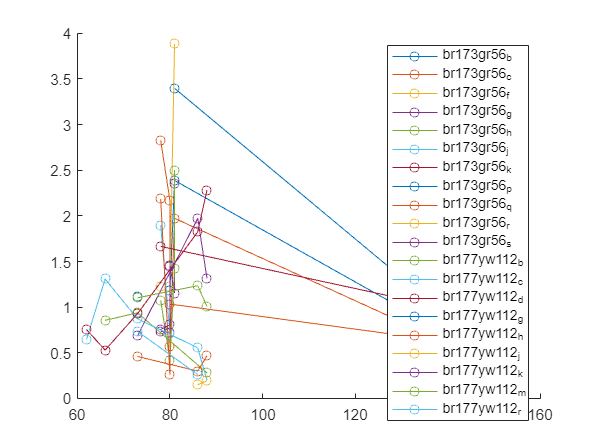

% figct = figct +1;
% figure(figct);clf;hold on
fontname = 'Franklin Gothic Heavy';

% extract the fano factors for distinct syllables
    filenames = spikeStats.casenames;
    % Initialize an empty cell array for the extracted parts
    extractedParts = cell(size(filenames));

    for i = 1:length(filenames)
        filename = filenames{i};
        
        % Find indices of underscores in the filename
        underscoreIndices = strfind(filename, '_');
        extractedParts{i} = filename(1:underscoreIndices(2)-1);
        case_days(i) = str2double(filename(underscoreIndices(2)+4:end));
    end

    % change neuron ID to days
    case_days(case_days == 661 | case_days == 662) = 66; 
    case_days(case_days == 801 | case_days == 802 | case_days == 803) = 80;
    case_days(case_days == 811 | case_days == 812) = 81;
    
    % Find unique values and their first index of occurrence
    [uniqueParts, ~, idxUnique] = unique(extractedParts);
    
    % idxUnique now holds indices of extractedParts that map back to the original list of filenames
    % To find the unique indices corresponding to the original list of filenames:
    uniqueIndices = arrayfun(@(x) find(idxUnique == x, 1, 'first'), 1:length(uniqueParts));

    % for each unique syllable, create vectors of the days and the
    % corresponding fano factors
    uniqueSyl = uniqueParts;
    for ii = 1:length(uniqueSyl)
        uniqueSyl(ii);
        syl_idx = find(idxUnique == ii);
        syl_ffs{ii} = spikeStats.fano_factor(syl_idx);
        syl_casenames{ii} = spikeStats.casenames(syl_idx);
        syl_days{ii} = case_days(syl_idx);
    end

% Plot the fano factor of a distinct syllable over time
figure; hold on
for j = 1:length(uniqueSyl)
    plot(syl_days{j}, syl_ffs{j},'-o')
end
legend(uniqueSyl)

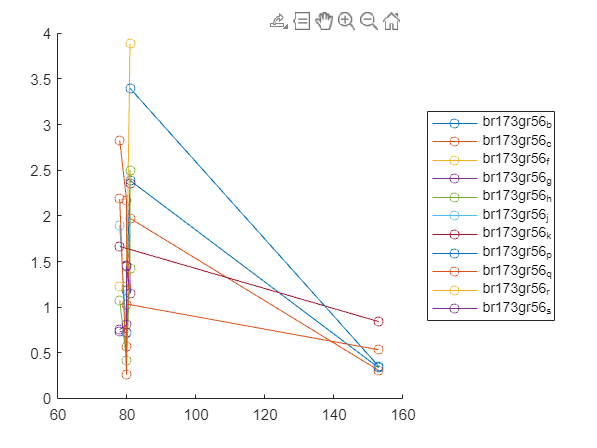


% plot for each bird
figure; hold on
which = 1:11;
for j = which
    plot(syl_days{j}, syl_ffs{j},'-o')
end
legend(uniqueSyl(which),Location="eastoutside")

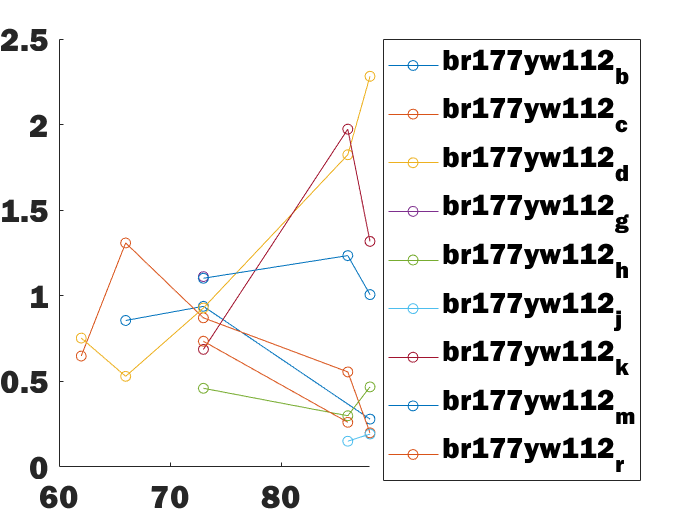


figure; hold on
which = 12:20;
for j = which
    plot(syl_days{j}, syl_ffs{j},'-o')
end
legend(uniqueSyl(which),Location = "eastoutside")
set(gca,'FontSize',20,'FontName',fontname)
% set(gcf,'Visible','On')


% PLOT for individual syllables
% for j = 1:length(uniqueSyl)
%     figure; plot(syl_days{j}, syl_ffs{j},'-o')
%     title(uniqueSyl(j))
%     xlim([62 160])
%     ylim([0 4])
% end

Plot fano factor by grouping adults vs juvniles


%Adult
s2=scatter(mature.mean_fr,mature.fano_factor,80,'filled','diamond','MarkerFaceAlpha',0.7);

Unable to resolve the name 'mature.mean_fr'.

s2.MarkerFaceColor = '#51154B';
%Juveniles
s3=scatter(juv_early.mean_fr,juv_early.fano_factor,80,'filled','o','MarkerFaceAlpha',0.7);
s3.MarkerFaceColor = '#EA63C2';

xlabel('Spike Rate (Hz)')
ylabel('FanoFactor')
legend({'adult';'juvenile'},"Location","northeast")
legend('boxoff')
% ylim([0 4])
% xlim([0 300])
% title(['Entropy v Spike rates in ' num2str(motor_window*1000) ' ms'])
set(gca,'FontSize',20,'FontName',fontname)
set(gcf,'Visible','On')

function plotHistograms(allCases, days, yclr, cclr, rclr, linewidth)
    % Define common plotting parameters
    xlims = [2500 4500];
    ylims = [0 0.55];
    binWidth = 100;
    normalization = 'probability';
    displayStyle = 'stairs';
    ytix = [0 0.5];
    xtix = [3000 4000]
    fontname = 'Franklin Gothic Heavy';
    
    for i = 1:length(days)
        figure;
        day = days(i);

        if day==62|day==661|day==662
            color = yclr; % Use 'yclr' for 'y' cases
        else
            color = cclr; % Use 'cclr' for 'c' cases
        end
        
        % Plot for 'c' cases
        cData = allCases.(['br177yw112_c_day' num2str(day)]).weighted_avg_pitch;
        cHist = histogram(cData, 'BinWidth', binWidth, 'Normalization', normalization, 'DisplayStyle', displayStyle);
        cHist.EdgeColor = color; 
        cHist.LineWidth = linewidth;
        xlabel('Pitch (Hz)')
        xlim(xlims);
        ylim(ylims);
        yticks(ytix);
        xticks(xtix);
        title(['Day ' num2str(day)])
        set(gca,'FontSize',20,'FontName',fontname)
        hold on;
        
        % Check if 'r' data exists for the day
        rFieldName = ['br177yw112_r_day' num2str(day) '.weighted_avg_pitch']
        if day==68|day==73|day==86|day==88
            % rData = allCases.(rFieldName);
            rData = allCases.(['br177yw112_r_day' num2str(day)]).weighted_avg_pitch;
            rHist = histogram(rData, 'BinWidth', binWidth, 'Normalization', normalization, 'DisplayStyle', displayStyle);
            rHist.EdgeColor = rclr; % Use 'rclr' for 'r' cases
            rHist.LineWidth = linewidth;
        end
        
    end
end
